# Robust Control of a Multivariable Experimental Four-Tank System

The goal is to explore some results of the two papers

-  K. H. Johansson. The Quadruple-Tank Process.- A multivariable laboratory process with an adjustable zero. IEEE Control Systems Technology, 2000;

- Rajanikanth Vadigepalli, Edward P. Gatzke, and Francis J. Doyle III, Robust Control of a Multivariable Experimental Four-Tank System. Ind. Eng. Chem. Res. 2001.

regarding the analysis of the properties of a multivariable Four-Tank System with 2 inputs and 2 outputs. We will also provide controllers for robust stabilizing the linear tangent model of the non linear system around the origin. Our dissertation will follow these keypoints:

- analysis of the eventual Minimum Phase property of the linearized system depending on the choice of parameters;

- finding the directions of the zeros and the poles of the linearized system and explore possible implications;

- showing the limitations due to the presence of eventual Non Minimum Phase zeros;

- introducing increasing uncertainty and trying to develop some robust decentralized controllers;

- exploring some decoupling approaches.

The goal is to control the levels $h_1$ and $h_2$ in the two lower tanks using the two pumps. The plants control inputs are the two input voltages of the pumps, $u_1$ and $u_2$. The fòow produced by pump i corresponding to a voltage $u_i$ is $k_{i\;} u_i$. The i-th valve distributes the output ow of the pump by sending $\gamma_{i\;} k_i {\;u}_i$ to the lower tank and the remaining $\left(1-\gamma_i \right)\;\;k_i {\;u}_i$ to the upper tank. Clearly $\gamma_1 ,\gamma_2 \in \left\lbrack 0,1\right\rbrack$. The gravity acceleration is $g$ while $A_i$ is the cross section area of tank i and $c_i$ is the cross-section area of the outlet hole of each tank. A sensor provides an output voltage proportional (with constant $k_t$) to the water height $k_i$, therefore the two measured outputs (two sensors with same $k_t$) are


$$y_1 =k_{t\;} h_{1,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;} y_2 =k_{t\;} h_2$$


Denoting with ${h^0 }_i$ i the height at the equilibrium in each tank, the time costants are given by:    $\tau_i =\frac{A_i }{c_i }\sqrt{\frac{2{{\;h}^0 }_i }{g}}$

The values of these parameters are taken from the Johansson' paper.

## 1. Poles and Zeros location and Minimum Phase property analysis.

The control object of our analysis is the MIMO transfer futnction matrix of the linearized model around an equilibrium point:

$G\left(s\right)=\left\lbrack \begin{array}{cc}
g_{11} \left(s\right) & g_{12} \left(s\right)\\
g_{21} \left(s\right) & g_{22} \left(s\right)
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{cc}
\frac{\gamma_{1\;} k_{1\;} n_1 }{\left(1+\tau_1 s\right)} & \frac{\left(1-\gamma_2 \right){\;k}_{2\;} n_1 }{\left(1+\tau_1 s\right)\left(1+\tau_3 s\right)}\\
\frac{\left(1-\gamma_1 \right){\;k}_{1\;} n_2 }{\left(1+\tau_2 s\right)\left(1+\tau_4 s\right)} & \frac{\gamma_{2\;} k_2 {\;n}_2 }{\left(1+\tau_2 s\right)}
\end{array}\right\rbrack$   with $n_i =\frac{k_t \;\tau_i }{A_i }\;$  and $i=1,2\ldotp$

Let us first of all compute the poles and the zeros.

We know that in a MIMO system the tranfer function's poles can be computed as the roots of the pole polynomial. The pole polynomial $P_d \left(s\right)$, i.e. the least common denominator of all non-zero minors of all orders of G(s).    

The minors of order 1 are the entries $g_{\textrm{ij}} \left(s\right)\;$of the matrix, while the only minor of order 2 is the transfer function determinant:

$\det \left\lbrack G\left(s\right)\right\rbrack =\;\frac{\gamma_1 {\;n}_1 \;k_1 \;\gamma_{2\;} k_2 \;n_2 }{\left(1+\tau_1 s\right)\left(1+\tau_2 s\right)}-\frac{\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)\;k_1 {\;k}_{2\;} n_1 \;n_2 }{\left(1+\tau_1 s\right)\left(1+\tau_2 s\right)\;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)}=\frac{\;k_1 {\;k}_{2\;} n_1 \;n_2 \;\left(\;\gamma_1 \;\gamma_{2\;} \;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)-\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)\right)}{\left(1+\tau_1 s\right)\left(1+\tau_2 s\right)\;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)}$ .

so $P_d \left(s\right)=\;$$\left(1+\tau_1 s\right)\left(1+\tau_2 s\right)\;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)$.

Then we can state that the poles of the transfer function are $-\frac{1}{\tau_i }\;\textrm{for}\;i\;=1,2,3,4,$  each of them with multeplicity equal to 1.

Similar considerations can be done for the computation of the zero. In the general case, the zeros can be computed as the roots of the zero polynomial $P_z \left(s\right),$ i.e. the greatest common divisor of all the numerators of all order r (normal rank) minors of G(s), provided that these have been adjusted so to have the pole polynomial as denominator. So if the normal rank of $G\left(s\right)\;$is 2,  we need to check only the minor of order 2, i. e. the determinant of the matrix.

Additionally, becuse of the fact that the transfer function is square (p = q = 2),  we could directly say that the solutions of $\det \left\lbrack G\left(s\right)\right\rbrack =$ 0 gives the transmission zeros which do not coincide with a pole.

Let's check when the determinant is different from zero. If it is equal to zero only at few values (normal rank = 2), we can state that such values are the transmission zeros of the transfer function.


$$\det \left\lbrack G\left(s\right)\right\rbrack =\frac{\;k_1 {\;k}_{2\;} n_1 \;n_2 \;\left(\;\gamma_1 \;\gamma_{2\;} \;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)-\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)\right)}{\left(1+\tau_1 s\right)\left(1+\tau_2 s\right)\;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)}=0\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;k_1 {\;k}_{2\;} n_1 \;n_2 \;\left(\;\gamma_1 \;\gamma_{2\;} \;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)-\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)\right)=0\ldotp \;\;\;\;\;$$


so: 


$$k_1 {\;k}_{2\;} n_1 \;n_2 \;\left(\;\gamma_1 \;\gamma_{2\;} \;\left(1+\tau_4 s+\tau_{3\;} s+\tau_3 \tau_4 {\;s}^2 \right)-\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)\right)=0\;$$
   
$$\Rightarrow \;\;\;\;$$

$$k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\left(\right.} \;\left(\tau_{4\;} +\tau_3 \right)\;s+\left(k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \gamma_{1\;} \gamma_{2\;} \tau_3 \;\tau_{4\;} \right)\;s^2 \;+\;\left(k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \gamma_{1\;} \gamma_{2\;} -k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \;\left(1-\gamma_1 \right)\;\left(1-\gamma_2 \right)\;\right)=0$$


a polynomial of order 2 whoose roots are:

    $z_{1,2} =\frac{-b\pm \;\sqrt{b^2 -4\;\textrm{ac}}}{2a}$, with $b=\;$$k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\left(\right.} \;\left(\tau_{4\;} +\tau_3 \right)\;$,   a = $\left(k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \gamma_{1\;} \gamma_{2\;} \tau_3 \;\tau_{4\;} \right)$,     $c=$$\left(k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \gamma_{1\;} \gamma_{2\;} -k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \;\left(1-\gamma_1 \right)\;\left(1-\gamma_2 \right)\;\right)$

and consequently the term     $-4\textrm{ac}=\;\;\;-4\;{\left(k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \right)}^{2\;} {\gamma^2 }_{1\;} \gamma_{2\;}^2 \;\tau_{3\;} \tau_4 +4\;{\left(k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \right)}^{2\;} {\left(1-\gamma_1 \right)}_{\;} {\;\left(1-\gamma_2 \right)}_{\;\;}^{\;} \;\tau_{3\;} \tau_4$         = $\;\;\;\;\;\;4\;{\left(k_{1\;} k_{2\;} \;n_{1\;} n_{2\;\;} \right)}^{2\;}$ $\tau_{3\;} \tau_4$    (${\left(1-\gamma_1 \right)}_{\;} {\;\left(1-\gamma_2 \right)}_{\;\;}^{\;}$ - ${\gamma^2 }_{1\;} \gamma_{2\;}^2$)

So, for the physics of the system, parameters will never be such that these two solutions are complex, and they costitutes the only two values with respect to which the matrix G(s) loses rank. So G(s) has normal rank equal to 2, and that solutions are the symbolical two trasmission zeros of the trasfer function.

Let us validate our computations using the calculator:

clear all
close all
clf

syms g1 g2 k1 k2 n1 n2 t1 t2 t3 t4 s  A1 A2 A3 A4  kc % inizializing the symbolic parameters of the system

G = [(g1*k1*n1/(1+t1*s)), ((1-g2)*k2*n1)/ ((1+t3*s)*(1+t1*s)); ((1-g1)*k1*n2)/ ((1+t2*s)*(1+t4*s)), (g2*k2*n2)/(1+t2*s)] % inizializing the plant

$$G = \left(\begin{array}{cc} \frac{g_{1}\,k_{1}\,n_{1}}{s\,t_{1}+1} & -\frac{k_{2}\,n_{1}\,\left(g_{2}-1\right)}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}\\ -\frac{k_{1}\,n_{2}\,\left(g_{1}-1\right)}{\left(s\,t_{2}+1\right)\,\left(s\,t_{4}+1\right)} & \frac{g_{2}\,k_{2}\,n_{2}}{s\,t_{2}+1} \end{array}\right)$$

d = det(G)

$$d = \frac{k_{1}\,k_{2}\,n_{1}\,n_{2}\,\left(g_{1}+g_{2}+g_{1}\,g_{2}\,s\,t_{3}+g_{1}\,g_{2}\,s\,t_{4}+g_{1}\,g_{2}\,s^{2}\,t_{3}\,t_{4}-1\right)}{\left(s\,t_{1}+1\right)\,\left(s\,t_{2}+1\right)\,\left(s\,t_{3}+1\right)\,\left(s\,t_{4}+1\right)}$$

eqn = d == 0;
zi = solve(eqn, s, 'ReturnConditions', true);
simplify(zi.s)

$$ans = \left(\begin{array}{c} -\frac{g_{1}\,g_{2}\,t_{3}-\sqrt{g_{1}\,g_{2}\,\left(4\,t_{3}\,t_{4}+g_{1}\,g_{2}\,{t_{3}}^{2}+g_{1}\,g_{2}\,{t_{4}}^{2}-4\,g_{1}\,t_{3}\,t_{4}-4\,g_{2}\,t_{3}\,t_{4}+2\,g_{1}\,g_{2}\,t_{3}\,t_{4}\right)}+g_{1}\,g_{2}\,t_{4}}{2\,g_{1}\,g_{2}\,t_{3}\,t_{4}}\\ -\frac{\sqrt{g_{1}\,g_{2}\,\left(4\,t_{3}\,t_{4}+g_{1}\,g_{2}\,{t_{3}}^{2}+g_{1}\,g_{2}\,{t_{4}}^{2}-4\,g_{1}\,t_{3}\,t_{4}-4\,g_{2}\,t_{3}\,t_{4}+2\,g_{1}\,g_{2}\,t_{3}\,t_{4}\right)}+g_{1}\,g_{2}\,t_{3}+g_{1}\,g_{2}\,t_{4}}{2\,g_{1}\,g_{2}\,t_{3}\,t_{4}} \end{array}\right)$$

These are the result we obtained, barring semplifications.

From the above analysis, it is easy to verify the properties of those zeros.

- First of all, from the expresion of $z_{1,2}$, we can see that if $\gamma_1 +\gamma_2 =1,\;$c is always equal to 0, so $z_1 =0\;$and $z_{2\;} \;$is Re[ ] < 0.

- secondly, if  ${0<\;\gamma }_1 +\gamma_2 <1,\;$ the quantity -4ac is always >0,  because the quantity ${\left(1-\gamma_1 \right)}_{\;} {\;\left(1-\gamma_2 \right)}_{\;\;}^{\;}$ is greater that ${\gamma^2 }_{1\;} \gamma_{2\;}^2$, so there is a positive zero and a negative one (system is non minimum-phase).

- thirdly, if  ${1<\;\gamma }_1 +\gamma_2 ,\;$ the quantity -4ac is always < 0,  because the quantity ${\left(1-\gamma_1 \right)}_{\;} {\;\left(1-\gamma_2 \right)}_{\;\;}^{\;}$ is smaller that ${\gamma^2 }_{1\;} \gamma_{2\;}^2$, so there are two negative zeros (system is minimum-phase). Naturally, since $\gamma_i \in \left\lbrack 0,1\right\rbrack \;\;\textrm{for}\;i=1,2,$ we can have at most that $\gamma_{1\;} +\gamma_2 =2\;\ldotp$So the minimum-phase conditions is simply ${1<\;\gamma }_1 +\gamma_2$ < 2.

Thinking about the physical interpetation these results make sense. We have a non minimum phase system if ${0<\;\gamma }_1 +\gamma_2 <1$, i.e. if the entering flow into the two lower thank ( the ones with respect to which we want to regulate the water level) is smaller than the total one entering the two upper tanks. Viceversa, we have minimum phase property is the upper tanks receive more flow tha the others.

If instead the total flow going to the left tanks 1 and 3 is equal to the total flow going to the right tanks 2 and 4, we have to manage with some more difficulties derived by the presence of the zero in 0.

Note that:

$\textrm{num}\;\left(\det \left(G\left(s\right)\right)\right)=\;\;\;k_1 {\;k}_{2\;} n_1 \;n_2 \;\left(\;\gamma_1 \;\gamma_{2\;} \;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)-\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)\right)\;\;\;\;\;=\;\;\;k_1 {\;k}_{2\;} n_1 \;n_2 \;\gamma_1 \;\gamma_{2\;} \;\left(\;\;\left(1+\tau_3 s\right)\left(1+\tau_4 s\right)-\frac{\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)}{\gamma_1 \;\gamma_{2\;} }\right)\;$.

So, in the case in which $\gamma_1 \to 1\;$and $\gamma_2 \to 1$, we have that $\frac{\left(1-\gamma_2 \right)\left(1-\gamma_1 \right)}{\gamma_1 \;\gamma_{2\;} }$ $\to 0\;$and $z_{1,2} \to$$\left(1+\tau_{3,4} \right)$ $k_1 {\;k}_{2\;} n_1 \;n_2 \;$, so  the two zeros of the transfer function are close to be coincident with the two poles $-\frac{1}{\tau_3 }$, $-\frac{1}{\tau_4 }$.

Note also that if one of the two or both $\gamma_{i\;} =0,$ we have not transimition zeros in the transfer function.

## 2. Directions of the zeros and the poles, blocking property of the zeros.

In order to compute the zeros directions, we need a minimal realization {A,B,C,D}: without it, we could not use the useful results about the system matrix.

Let us check if the proposed realization in the Johansson's paper is minimal.

To do this, we need to check the observability and the controllability properties of the natural modes of that system. If the system is fully controllable and fully observable, we can state that the realizazion  {A,B,C,D} is minimal.

So let us compute the Observability and the Controllability Matrices and check if they are full rank.

A = [ -1/t1, 0 , A3/(A1*t3), 0; 0 , -1/t2, 0 A4/(A2*t4); 0, 0, -1/t3, 0; 0,0,0, -1/t4]; % matrix A
C = [kc, 0,0,0; 0, kc,0,0];    % matrix C
B = [(g1*k1)/A1, 0; 0, (g2*k2)/A2; 0, (1-g2)*k2/A3; (1-g1)*k1/A4, 0]; % matrix B
D = zeros(2,2);

A_2 = A*A;
A_3 = A*A*A;
Obv = [C; C*A; C*A_2; C*A_3];  % observability matrix
rank(Obv)

ans = 4

Con = [B , A*B, A_2*B, A_3*B];   % controllability matrix
rank(Con)

ans = 4

Both matrices have rank = 4, equal to the dimention of the state. This implies that the system is fully controllable and observable. The state space representation is then a minimal realization of the transfer function G(s).

Let us now substitute the symbolical quantities with the values used in the Johansson paper and try to compute these quantities.

Our considerations on the zeros and poles directions will regard the operating points $P_-$ and $P_+$ and around which the system exhibits respectively minimum-phase (MP) and non-minimum-phase (NMP) characteristics.

A1_n = 28; % cm^2
A3_n = 28; % cm^2
A2_n = 32; % cm^2
A4_n = 32; % cm^2
c1_n = 0.071; % cm^2
c2_n = 0.057; % cm^2
c3_n = 0.071; % cm^2
c4_n = 0.057; % cm^2
kc_n= 0.5;  % V/cm
g_n = 981; %cm/s^2


% MP parameters

h01_mp = 12.4; % cm
h02_mp = 12.7; % cm
h03_mp = 1.8;  % cm
h04_mp = 1.4;  % cm

k1_mp = 3.33; % cm^3/Vs
k2_mp = 3.35; % cm^3/Vs

g1_mp = 0.7;
g2_mp = 0.6;

t1_mp = (A1_n/c1_n) * sqrt(2*h01_mp/g_n);   % s
t2_mp = (A2_n/c2_n) * sqrt(2*h02_mp/g_n);   % s
t3_mp = (A3_n/c3_n) * sqrt(2*h03_mp/g_n);   % s
t4_mp = (A4_n/c4_n) * sqrt(2*h04_mp/g_n);   % s

n1_mp = (kc_n* t1_mp)/A1_n;
n2_mp = (kc_n* t2_mp)/A2_n;

% NMP parameters

h01_nmp = 12.6; % cm
h02_nmp = 13; % cm
h03_nmp = 4.8;  % cm
h04_nmp = 4.9;  % cm

k1_nmp = 3.14; % cm^3/Vs
k2_nmp = 3.29; % cm^3/Vs

g1_nmp = 0.43;
g2_nmp = 0.34;

t1_nmp = (A1_n/c1_n) * sqrt(2*h01_nmp/g_n);  % s
t2_nmp = (A2_n/c2_n) * sqrt(2*h02_nmp/g_n);  % s
t3_nmp = (A3_n/c3_n) * sqrt(2*h03_nmp/g_n);  % s
t4_nmp = (A4_n/c4_n) * sqrt(2*h04_nmp/g_n);  % s

n1_nmp = (kc_n* t1_nmp)/A1_n;
n2_nmp = (kc_n* t2_nmp)/A2_n;


% MP state space inizialization

A_mp = eval(subs(A, [A1, A2, A3,A4,  t1, t2, t3 ,t4], [A1_n, A2_n, A3_n, A4_n, t1_mp, t2_mp, t3_mp, t4_mp]));
B_mp = eval(subs(B, [A1, A2, A3,A4, g1, g2, k1 , k2], [A1_n, A2_n, A3_n, A4_n, g1_mp, g2_mp, k1_mp, k2_mp]));
C_mp = eval(subs(C, kc, kc_n));
D_mp = eye(2)*0;

G_sys_mp = ss(A_mp, B_mp, C_mp, D_mp);

% NMP state space inizialization

A_nmp = eval(subs(A, [A1, A2, A3,A4,  t1, t2, t3 ,t4], [A1_n, A2_n, A3_n, A4_n, t1_nmp, t2_nmp, t3_nmp, t4_nmp]));
B_nmp = eval(subs(B, [A1, A2, A3,A4, g1, g2, k1 , k2], [A1_n, A2_n, A3_n, A4_n, g1_nmp, g2_nmp, k1_nmp, k2_nmp]));
C_nmp = eval(subs(C, kc, kc_n));
D_nmp = eye(2)*0;

G_sys_nmp = ss(A_nmp, B_nmp, C_nmp, D_nmp);

s = tf('s');

% inizializing the transfer function of the plant with MP property

Gs_mp = [(g1_mp*k1_mp*n1_mp/(1+t1_mp*s)), ((1-g2_mp)*k2_mp*n1_mp)/ ((1+t3_mp*s)*(1+t1_mp*s)); ((1-g1_mp)*k1_mp*n2_mp)/ ((1+t2_mp*s)*(1+t4_mp*s)), (g2_mp*k2_mp*n2_mp)/(1+t2_mp*s)]

Gs_mp =
 
  From input 1 to output...
          2.61
   1:  ----------
       62.7 s + 1
 
                1.41
   2:  ----------------------
       2709 s^2 + 120.3 s + 1
 
  From input 2 to output...
                1.5
   1:  ----------------------
       1498 s^2 + 86.59 s + 1
 
          2.837
   2:  -----------
       90.34 s + 1
 
Continuous-time transfer function.
Model Properties


% inizializing the  transfer function of the plant with NMP property

Gs_nmp = [(g1_nmp*k1_nmp*n1_nmp/(1+t1_nmp*s)), ((1-g2_nmp)*k2_nmp*n1_nmp)/ ((1+t3_nmp*s)*(1+t1_nmp*s)); ((1-g1_nmp)*k1_nmp*n2_nmp)/ ((1+t2_nmp*s)*(1+t4_nmp*s)), (g2_nmp*k2_nmp*n2_nmp)/(1+t2_nmp*s)] 

Gs_nmp =
 
  From input 1 to output...
          1.524
   1:  -----------
       63.21 s + 1
 
               2.556
   2:  ----------------------
       5128 s^2 + 147.5 s + 1
 
  From input 2 to output...
               2.451
   1:  ----------------------
       2466 s^2 + 102.2 s + 1
 
         1.597
   2:  ----------
       91.4 s + 1
 
Continuous-time transfer function.
Model Properties


Let's first of all compute the zeros of the system in the way explained in point 1, both for MP and NMP cases, i.d. seeing the values for wihich $\det \left(G\left(s\right)\right)=0\ldotp$

det_mp = (k1_mp*k2_mp*n1_mp*n2_mp*(g1_mp + g2_mp + g1_mp*g2_mp*s*t3_mp + g1_mp*g2_mp*s*t4_mp + g1_mp*g2_mp*s^2*t3_mp*t4_mp - 1))/((s*t1_mp + 1)*(s*t2_mp + 1)*(s*t3_mp + 1)*(s*t4_mp + 1));
zi_mp = zero(det_mp)   % computation of the 2 minimum phase transmission zeros

zi_mp =    -0.0580
   -0.0172


det_nmp = (k1_nmp*k2_nmp*n1_nmp*n2_nmp*(g1_nmp + g2_nmp + g1_nmp*g2_nmp*s*t3_nmp + g1_nmp*g2_nmp*s*t4_nmp + g1_nmp*g2_nmp*s^2*t3_nmp*t4_nmp - 1))/((s*t1_nmp + 1)*(s*t2_nmp + 1)*(s*t3_nmp + 1)*(s*t4_nmp + 1));
zi_nmp = zero(det_nmp)   % computation of the 1 minimum phase and the 1 non minimum phase transmission zeros

zi_nmp =    -0.0562
    0.0128


As we can see, the signs of the zeros are coherent with what we expected. Let's now compute the system matrix $S\left(s\right)$ and see if its zeros coincides with the zero of the transfer function.

We have to remember that since the system is square (p = q), left and right zeros coincides. Furthermore, since the realization is minimal, the zeros of the system matrix $S\left(s\right)$ with respect to which it drops rank are ONLY the transmition zeros, there is no presence of invariant zeros.

syms s
sys_matrix = [s*eye(4)- A, -B; C, D]     % inzializing the system matrix

$$sys\_matrix = \left(\begin{array}{cccccc} s+\frac{1}{t_{1}} & 0 & -\frac{A_{3}}{A_{1}\,t_{3}} & 0 & -\frac{g_{1}\,k_{1}}{A_{1}} & 0\\ 0 & s+\frac{1}{t_{2}} & 0 & -\frac{A_{4}}{A_{2}\,t_{4}} & 0 & -\frac{g_{2}\,k_{2}}{A_{2}}\\ 0 & 0 & s+\frac{1}{t_{3}} & 0 & 0 & \frac{k_{2}\,\left(g_{2}-1\right)}{A_{3}}\\ 0 & 0 & 0 & s+\frac{1}{t_{4}} & \frac{k_{1}\,\left(g_{1}-1\right)}{A_{4}} & 0\\ \mathrm{kc} & 0 & 0 & 0 & 0 & 0\\ 0 & \mathrm{kc} & 0 & 0 & 0 & 0 \end{array}\right)$$

sys_matrix_mp = eval([s*eye(4)-A_mp, -B_mp; C_mp, D_mp]);   % inzializing the system matrix MP
sys_matrix_nmp = eval([s*eye(4)-A_nmp, -B_nmp; C_nmp, D_nmp]);   % inzializing the system matrix NMP

det_sys_mat_mp = eval(det(sys_matrix_mp));        % determinant of MP system matrix
det_sys_mat_nmp = eval(det(sys_matrix_nmp));      % determinant of NMP system matrix

eq5 = det_sys_mat_mp == 0;            % finding values with respect to which the system matrix drops rank
eq6 = det_sys_mat_nmp == 0;

zi_mp= eval(solve(eq5,s))      % 2 MP zeros

zi_mp =    -0.0580
   -0.0172


zi_nmp= eval(solve(eq6,s))     % 1 MP 1 NMP zeros

zi_nmp =    -0.0562
    0.0128


Which proves our expectations. Let us further validate our results using the MATLAB function tzero() to see if there is matching of computations. 

tzero(G_sys_mp)

ans =    -0.0580
   -0.0172


tzero(G_sys_nmp)

ans =    -0.0562
    0.0128


Verified that the computed two pair of zeros are right, we can now find the zero directions solving the two problems for every zero:

$\left\lbrack \begin{array}{cc}
\textrm{zI}-A & -B\\
C & D
\end{array}\right\rbrack \;\;\left\lbrack \begin{array}{c}
\xi_z \\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$   ,    ${\left\lbrack \begin{array}{cc}
\eta_z  & \omega_z 
\end{array}\right\rbrack }^{T\;} \;\left\lbrack \begin{array}{cc}
\textrm{zI}-A & -B\\
C & D
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$      with  $\left\lbrack \begin{array}{c}
\xi_z \\
v_z 
\end{array}\right\rbrack$$\not=$ $\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$   and   ${\left\lbrack \begin{array}{cc}
\eta_z  & \omega_z 
\end{array}\right\rbrack }^{T\;}$$\not=$${\;\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack }^T$

 where $S\left(z\right)=$ $\left\lbrack \begin{array}{cc}
\textrm{zI}-A & -B\\
C & D
\end{array}\right\rbrack$ is the system matrix computed at one possible zero,  $n=$ $\left\lbrack \begin{array}{c}
\xi_z \\
v_z 
\end{array}\right\rbrack$,  $m=\;\left\lbrack \begin{array}{cc}
\eta_z  & \omega_z 
\end{array}\right\rbrack$,  respectively the right and left generalized eigenvector  associated to z. 

The vector $\xi_z$ $\in R^{n\;\;}$costitutes the zero state direction ,  $v_z$ $\in R^{q\;\;}$the zero input direction,  $\omega_z$ $\in R^{p\;\;}$the zero output direction. 

We can reformulate this two problems as a generalized eigenvalue problem:

 
$$\begin{array}{l}
G\;n=z\;M\;n\\
m^T \;G=z\;m{\;}^T M
\end{array}$$


with $G=\left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack$ and $M=\left\lbrack \begin{array}{cc}
I & 0\\
0 & 0
\end{array}\right\rbrack$, and find $n,m\;$easily.

Let us follow this approach.

M = [eye(4), B_mp*0;C_mp*0, D_mp];  % inizialization of M

G_mp = [A_mp,B_mp; C_mp, D_mp];      % inizialization of G (MP zeros)
G_nmp = [A_nmp,B_nmp;C_nmp, D_nmp];  % inizialization of G (1 NMP zeros)

[na,za,ma] = eig(G_mp,M)    % computing n and m

na =          0         0         0         0    0.0000         0
         0         0         0         0         0    0.0000
         0    1.0000   -1.0000   -0.0000   -0.0000    0.0000
         0   -0.9714   -0.6361   -0.0000    0.0000         0
    1.0000   -0.5028    0.5028         0    1.0000   -0.0395
         0    0.5156    0.3377   -1.0000   -0.0000    1.0000


za =        Inf         0         0         0         0         0
         0   -0.0172         0         0         0         0
         0         0   -0.0580         0         0         0
         0         0         0       Inf         0         0
         0         0         0         0       Inf         0
         0         0         0         0         0       Inf


ma =     0.0000    0.3750    0.3750         0         0         0
    0.0000   -0.4847    0.7401   -0.0000         0         0
         0    0.6361   -0.9714         0         0         0
    0.0000   -1.0000   -1.0000         0         0         0
    1.0000   -0.0009   -0.0316         0    1.0000         0
    0.0409    0.0059   -0.0695   -1.0000         0    1.0000


Here we can see the generalized eigenvectors associated to the two zeros $z_1 =-0\ldotp 0172\;\;\;$and ${\;z}_2 =-0\ldotp 0172$  for the equilibrium point $P_-$.

The columns 2,3 of the matrices $n_a$, $m_a$ are respectively the two right and left generalized eigenvectos; while the first 4 elements of the 2° and 3° columns of $n_a$ are the zeros state direction $\xi_z$ and the last two elements of the  2° and 3° columns of $n_a$ and $m_a$ are respectively the zero input and output directions $v_z$, $\omega_z$.

The following are the same quantities for the equilibrium point $P_+ \ldotp$

[nb,zb,mb] = eig(G_nmp,M)

nb =          0         0         0         0    0.0000         0
         0         0         0         0         0    0.0000
         0    1.0000   -1.0000    0.0000         0   -0.0000
         0   -0.9716   -0.7740         0    0.0000    0.0000
    1.0000   -0.5316    0.5316   -0.0557    1.0000    0.0946
         0    0.4953    0.3946   -1.0000   -0.0000    1.0000


zb =        Inf         0         0         0         0         0
         0    0.0128         0         0         0         0
         0         0   -0.0562         0         0         0
         0         0         0       Inf         0         0
         0         0         0         0       Inf         0
         0         0         0         0         0       Inf


mb =     0.0000    0.6755    0.5381         0         0         0
    0.0000   -1.0000    1.0000   -0.0000         0         0
    0.0000    0.4508   -0.4508         0         0         0
         0   -0.5824   -0.4639         0         0         0
    1.0000    0.0386   -0.0435         0    1.0000         0
    0.0481   -0.0474   -0.0906   -1.0000         0    1.0000


Let us now extract the velues specified before. 

csi_z_mp = na(1:4, 2:3)   % zero state directions for the two MP zeros of P-

csi_z_mp =          0         0
         0         0
    1.0000   -1.0000
   -0.9714   -0.6361


v_z_mp = na(5:6, 2:3)   % zero input directions for the two MP zeros of P-

v_z_mp =    -0.5028    0.5028
    0.5156    0.3377


csi_z_nmp = nb(1:4, 2:3)  % zero input state directions for the two zeros (one MP one NMP) of P+

csi_z_nmp =          0         0
         0         0
    1.0000   -1.0000
   -0.9716   -0.7740


v_z_nmp = nb(5:6, 2:3)   % zero input directions for the two zeros (one MP one NMP) of P+

v_z_nmp =    -0.5316    0.5316
    0.4953    0.3946


w_z_mp = ma(5:6, 2:3)   % zero output directions for the two MP zeros of P-

w_z_mp =    -0.0009   -0.0316
    0.0059   -0.0695


w_z_nmp = mb(5:6, 2:3)   % zero output directions for the two zeros (one MP one NMP) of P+

w_z_nmp =     0.0386   -0.0435
   -0.0474   -0.0906


eta_z_nmp = mb(1:4, 2:3)   % zero output state directions for the two zeros (one MP one NMP) of P+

eta_z_nmp =     0.6755    0.5381
   -1.0000    1.0000
    0.4508   -0.4508
   -0.5824   -0.4639


From the inspection of the component of $\omega_z$, we can see that the direction of the NMP zeros is not a unit vector, so the effect of the RHP zero is distributed between both outputs.

Now we want to show the blocking property of these two pairs of transmition zeros.

In other words, we want to show that the outputs of the two system $y_1 \left(t\right)\equiv y_2 \left(t\right)\equiv 0\;\forall \;t>0,$exept for some small errors due to numerical digit approximations (always present in Matlab), provided that the inputs are set as $u_1 \left(t\right)=e^{z_1 t} v_{z_1 }$ and $u_2 \left(t\right)=e^{z_2 t} v_{z_2 } \;$and the inizial states  $x\left(0\right)=\xi_z$.

This means that every couple of inputs with such directions $v_z$,  with the form of an exponential with grow rate equal to $z_i$, will not be reproduced in non of the outputs provided that the system starts to evolve from the zero state direction $\xi_z$, thanks to the presence of the associated transmition zeros $z_i$. 

From the inspection of the component of $\xi_z$, we can state both for the MP and the NMP case that,  in order to the exhibition by the system of the blocking property of the zeros, the distances of the levels of the first two tanks $h_1$and $h_2$ from the height at the two equilibrium point ${h^0 }_1$ and ${h^0 }_2$ have to be equal to zero, the remaining 3 and 4 have to differ by the quantity specified in the other 2 elements of $\xi_z$, and the difference between the current voltages provided and the ones at the two equilibria has to be a signal with exponential form, grow rate equal to $z_i$, and the proportions in which the exponential should be present at the corresponding input equal to the components of $v_z$.

Let us try to visalize all of these things by simulations.

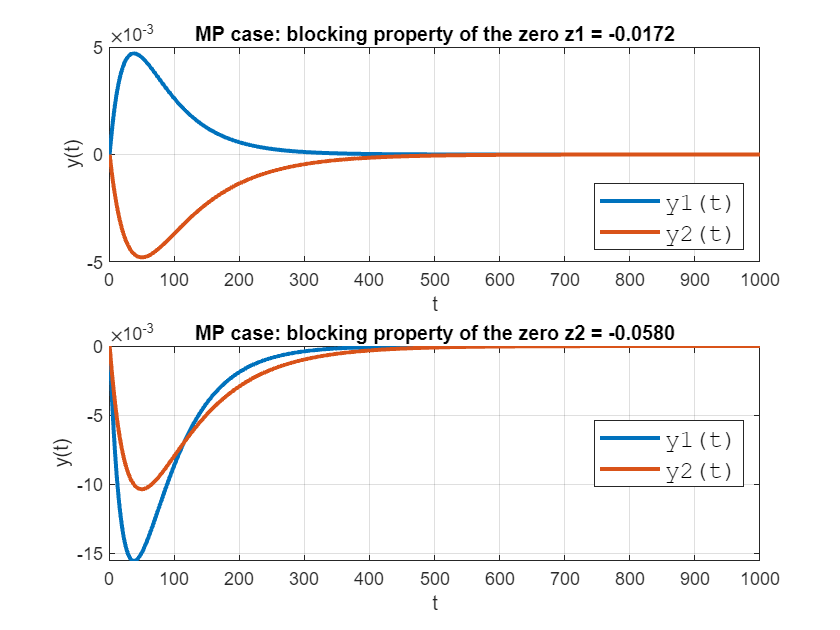

t = 1:0.001:1000; % inizializing the time span

u1_mp = [zeros(length(t),1), zeros(length(t),1)];   % inizializing u_1 at P_
u2_mp = [zeros(length(t),1), zeros(length(t),1)];    % inizializing u_2 at P_

u1_nmp = [zeros(length(t),1), zeros(length(t),1)];   % inizializing u_1 at P+
u2_nmp = [zeros(length(t),1), zeros(length(t),1)];   % inizializing u_2 at P+

% building the exponential signals with directions v_z :

for i =1 : length(t)
    u1_mp(i,1) = exp(zi_mp(2)*t(i))* v_z_mp(1,1);
    u1_mp(i,2) = exp(zi_mp(2)*t(i))* v_z_mp(2,1);
end

for i =1 : length(t)
    u2_mp(i,1) = exp(zi_mp(1)*t(i))* v_z_mp(1,2);
    u2_mp(i,2) = exp(zi_mp(1)*t(i))* v_z_mp(2,2);
end

for i =1 : length(t)
    u1_nmp(i,1) = exp(zi_nmp(2)*t(i))* v_z_nmp(1,1);
    u1_nmp(i,2) = exp(zi_nmp(2)*t(i))* v_z_nmp(2,1);
end

for i =1 : length(t)
    u2_nmp(i,1) = exp(zi_nmp(1)*t(i))* v_z_nmp(1,2);
    u2_nmp(i,2) = exp(zi_nmp(1)*t(i))* v_z_nmp(2,2);
end


% simulating from inizial conditions csi_z:

y1 = lsim(G_sys_mp, u1_mp,t,  csi_z_mp(:,1));
y2 = lsim(G_sys_mp, u2_mp,t, csi_z_mp(:,2));

y3 = lsim(G_sys_nmp, u1_nmp,t, csi_z_nmp(:,1));
y4 = lsim(G_sys_nmp, u2_nmp,t, csi_z_nmp(:,2));

figure()

subplot(211)
plot(t, y1, 'LineWidth',2); grid
title("MP case: blocking property of the zero z1 = -0.0172");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')

subplot(212)
plot(t, y2, 'LineWidth',2); grid
title("MP case: blocking property of the zero z2 = -0.0580");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','East')

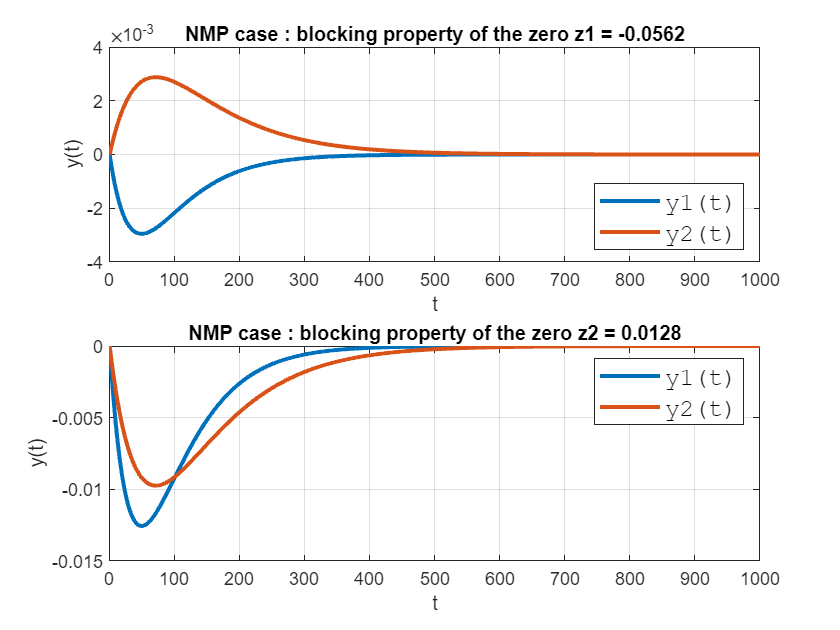

figure()
subplot(211)
plot(t, y3, 'LineWidth',2); grid
title("NMP case : blocking property of the zero z1 = -0.0562");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')

subplot(212)
plot(t, y4, 'LineWidth',2); grid
title("NMP case : blocking property of the zero z2 = 0.0128");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','NorthEast')

As we expected, the outputs are identically = 0 except for some small errors of the order of ${10}^{-3} \;$due to the numerical approximations.

In order investigate more in which way the effect of the RPH zero is distributed between the two outputs, we can also compute symbolically the zero output directions through the transfer function, as done in the Johansson's paper.

We start putting : $\omega_z^{T\;} \;G\left(z\right)=0\ldotp$

syms wz1 wz2

wz = [wz1; wz2];

res = wz'*G 

$$res = \left(\begin{array}{cc} \frac{g_{1}\,k_{1}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{s\,t_{1}+1}-\frac{k_{1}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}\,\left(g_{1}-1\right)}{\left(s\,t_{2}+1\right)\,\left(s\,t_{4}+1\right)} & \frac{g_{2}\,k_{2}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}}{s\,t_{2}+1}-\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}\,\left(g_{2}-1\right)}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)} \end{array}\right)$$

Then we solve for $\gamma_2 \;$as suggested in the Johansson's paper.

eq7 = res(2) == 0

$$eq7 = \frac{g_{2}\,k_{2}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}}{s\,t_{2}+1}-\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}\,\left(g_{2}-1\right)}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}=0$$

solution = solve(eq7,g2)   % solving for gamma2

$$solution = -\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(\frac{k_{2}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}}{s\,t_{2}+1}-\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}\right)\,\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}$$

Then we substitute this values in the original expression, we solve for $\omega_{\textrm{z1}}$ we simplify for $\frac{\omega_{\textrm{z1}} }{\omega_{\textrm{z2}} }$.

res1= eval(subs(res, g2, solution))  % substituting gamma2 in the original expression

$$res1 = \left(\begin{array}{cc} \frac{g_{1}\,k_{1}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{s\,t_{1}+1}-\frac{k_{1}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}\,\left(g_{1}-1\right)}{\left(s\,t_{2}+1\right)\,\left(s\,t_{4}+1\right)} & \frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}\,\left(\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(\frac{k_{2}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}}{s\,t_{2}+1}-\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}\right)\,\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}+1\right)}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}-\frac{{k_{2}}^{2}\,n_{1}\,n_{2}\,\bar{{\mathrm{wz}}_{1}}\,\bar{{\mathrm{wz}}_{2}}}{\left(\frac{k_{2}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}}{s\,t_{2}+1}-\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}\right)\,\left(s\,t_{1}+1\right)\,\left(s\,t_{2}+1\right)\,\left(s\,t_{3}+1\right)} \end{array}\right)$$

res2 = collect(res1, wz1)   % regrouping terms

$$res2 = \left(\begin{array}{cc} \frac{g_{1}\,k_{1}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{s\,t_{1}+1}-\frac{k_{1}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}\,\left(g_{1}-1\right)}{\left(s\,t_{2}+1\right)\,\left(s\,t_{4}+1\right)} & \frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}\,\left(\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(\frac{k_{2}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}}{s\,t_{2}+1}-\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}\right)\,\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}+1\right)}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}-\frac{{k_{2}}^{2}\,n_{1}\,n_{2}\,\bar{{\mathrm{wz}}_{1}}\,\bar{{\mathrm{wz}}_{2}}}{\left(\frac{k_{2}\,n_{2}\,\bar{{\mathrm{wz}}_{2}}}{s\,t_{2}+1}-\frac{k_{2}\,n_{1}\,\bar{{\mathrm{wz}}_{1}}}{\left(s\,t_{1}+1\right)\,\left(s\,t_{3}+1\right)}\right)\,\left(s\,t_{1}+1\right)\,\left(s\,t_{2}+1\right)\,\left(s\,t_{3}+1\right)} \end{array}\right)$$

eq8 = res2(1) ==0;
s2 = solve(eq8, wz1)   % solving for w_z1

$$s2 = \frac{{\mathrm{wz}}_{2}\,\bar{n_{2}}\,\left(\bar{g_{1}}-1\right)\,\left(\bar{s}\,\bar{t_{1}}+1\right)}{\bar{g_{1}}\,\bar{n_{1}}\,\left(\bar{s}\,\bar{t_{2}}+1\right)\,\left(\bar{s}\,\bar{t_{4}}+1\right)}$$

eq9 = wz1/wz2 == s2/wz2   % obtaining the Johansson's relation

$$eq9 = \frac{{\mathrm{wz}}_{1}}{{\mathrm{wz}}_{2}}=\frac{\bar{n_{2}}\,\left(\bar{g_{1}}-1\right)\,\left(\bar{s}\,\bar{t_{1}}+1\right)}{\bar{g_{1}}\,\bar{n_{1}}\,\left(\bar{s}\,\bar{t_{2}}+1\right)\,\left(\bar{s}\,\bar{t_{4}}+1\right)}$$

This relation shows that as $\gamma_1 \;$decreases, $\omega_{\textrm{z1}}$ increases and the effect of the zero is more relevant in the first output. Viceversa, as $\gamma_1$ increases $\omega_{\textrm{z1}}$ decreases and the zero has a more relevant effect for $y_2 \ldotp \;\;$This is intuitive: as much we provide less flow to one tank, harder to control is its level (for the increased effect of the NMP zero).

Let us now find the symbolical pole directions, remembering that $v_i^T B\;$are the input poles directions and ${{\textrm{Cu}}_i }$the output poles directions, where $v_i$ , ${u_i }$are respectively the left and the right eigenvectors associated with the eigenvalues of the matrix A.

[U, Di] = eig(A)   % computation of right eigenvectors

$$U = \left(\begin{array}{cccc} 1 & 0 & -\frac{A_{3}\,t_{1}}{A_{1}\,\left(t_{1}-t_{3}\right)} & 0\\ 0 & 1 & 0 & -\frac{A_{4}\,t_{2}}{A_{2}\,\left(t_{2}-t_{4}\right)}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$Di = \left(\begin{array}{cccc} -\frac{1}{t_{1}} & 0 & 0 & 0\\ 0 & -\frac{1}{t_{2}} & 0 & 0\\ 0 & 0 & -\frac{1}{t_{3}} & 0\\ 0 & 0 & 0 & -\frac{1}{t_{4}} \end{array}\right)$$

[V, Di] = eig(A.')   % computation of left eigenvectors (computed as columns)

$$V = \left(\begin{array}{cccc} \frac{A_{1}\,\left(t_{1}-t_{3}\right)}{A_{3}\,t_{1}} & 0 & 0 & 0\\ 0 & \frac{A_{2}\,\left(t_{2}-t_{4}\right)}{A_{4}\,t_{2}} & 0 & 0\\ 1 & 0 & 1 & 0\\ 0 & 1 & 0 & 1 \end{array}\right)$$

$$Di = \left(\begin{array}{cccc} -\frac{1}{t_{1}} & 0 & 0 & 0\\ 0 & -\frac{1}{t_{2}} & 0 & 0\\ 0 & 0 & -\frac{1}{t_{3}} & 0\\ 0 & 0 & 0 & -\frac{1}{t_{4}} \end{array}\right)$$

input_pole_vec = (V.')*B    % each row is the input direction associate to i-th eigenvalue (i-th pole)

$$input\_pole\_vec = \left(\begin{array}{cc} \frac{g_{1}\,k_{1}\,\left(t_{1}-t_{3}\right)}{A_{3}\,t_{1}} & -\frac{k_{2}\,\left(g_{2}-1\right)}{A_{3}}\\ -\frac{k_{1}\,\left(g_{1}-1\right)}{A_{4}} & \frac{g_{2}\,k_{2}\,\left(t_{2}-t_{4}\right)}{A_{4}\,t_{2}}\\ 0 & -\frac{k_{2}\,\left(g_{2}-1\right)}{A_{3}}\\ -\frac{k_{1}\,\left(g_{1}-1\right)}{A_{4}} & 0 \end{array}\right)$$

output_pole_vec = C*U    % each column is the output direction associate to i-th eigenvalue (i-th pole)

$$output\_pole\_vec = \left(\begin{array}{cccc} \mathrm{kc} & 0 & -\frac{A_{3}\,\mathrm{kc}\,t_{1}}{A_{1}\,\left(t_{1}-t_{3}\right)} & 0\\ 0 & \mathrm{kc} & 0 & -\frac{A_{4}\,\mathrm{kc}\,t_{2}}{A_{2}\,\left(t_{2}-t_{4}\right)} \end{array}\right)$$

It is interesting to evaluate these quantities in the parameters combination we analyzed in the point 1, the one in which $\gamma_1 =\gamma_2 =1\ldotp$ We saw that in such a case we have two zero-pole coincidences in $-\frac{1}{\tau_3 },-\frac{1}{\tau_4 }\ldotp$

We know that such a coincidence will bring to a zero-pole cancellation conditionally to several condition.

In particular we have:

- a pole/zero cancellation with loss of observability iff $\xi_z \parallel u_p ,\;$where $u_p$is the pole right eigenvector;

-  zero/pole cancellation with loss of controllability iff $\eta_z \parallel v_p ,\;$where $v_p$is the pole left eigenvector.

So let us evaluate the system numerically with $\gamma_1 =\gamma_2 =1$ and compute the poles and the zeros directions..

A_canc= eval(subs(A, [A1, A2, A3,A4,  t1, t2, t3 ,t4], [A1_n, A2_n, A3_n, A4_n, t1_mp, t2_mp, t3_mp, t4_mp]));
B_canc = eval(subs(B, [A1, A2, A3,A4, g1, g2, k1 , k2], [A1_n, A2_n, A3_n, A4_n, 1, 1, k1_mp, k2_mp]));
C_canc = eval(subs(C, kc, kc_n));
D_canc = eye(2)*0;

[U_canc, D] = eig(A_canc)   % computation of right eigenvectors 

U_canc =     1.0000         0   -0.8503         0
         0    1.0000         0   -0.8315
         0         0    0.5263         0
         0         0         0    0.5555


D =    -0.0159         0         0         0
         0   -0.0111         0         0
         0         0   -0.0419         0
         0         0         0   -0.0333


[V_canc, D] = eig(A_canc.') % computation of left eigenvectors

V_canc =          0    0.5263         0         0
         0         0         0    0.5555
    1.0000    0.8503         0         0
         0         0    1.0000    0.8315


D =    -0.0419         0         0         0
         0   -0.0159         0         0
         0         0   -0.0333         0
         0         0         0   -0.0111


input_pole_vec_canc = (V_canc.')*B_canc  % computation of input poles directions

input_pole_vec_canc =          0         0
    0.0626         0
         0         0
         0    0.0581


output_pole_vec_canc = C_canc*U_canc     % computation of output poles directions

output_pole_vec_canc =     0.5000         0   -0.4251         0
         0    0.5000         0   -0.4158


Gs_canc = [(k1_mp*n1_mp/(1+t1_mp*s)), 0; 0, (k2_mp*n2_mp)/(1+t2_mp*s)] % transfer function 

$$Gs\_canc = \left(\begin{array}{cc} \frac{524755527674329}{140737488355328\,\left(\frac{8824717582511237\,s}{140737488355328}+1\right)} & 0\\ 0 & \frac{2661902216441409}{562949953421312\,\left(\frac{6356781412397395\,s}{70368744177664}+1\right)} \end{array}\right)$$

G_ss_canc = ss(A_canc, B_canc, C_canc, D_canc);
tzero(G_ss_canc)

ans =    -0.0419
   -0.0333


As we expected we have two zeros/pole coincidences in $-\frac{1}{\tau_3 },-\frac{1}{\tau_4 }$.

G_canc = [A_canc,B_canc; C_canc, D_canc];      % inizialization of G (gamma1 = gamma2 = 1)

[n_canc,z_canc,m_canc] = eig(G_canc,M)    % computing n and m

n_canc =          0         0         0         0    0.0000         0
         0         0         0         0         0    0.0000
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
    1.0000         0   -0.3520         0    1.0000         0
         0    1.0000         0   -0.3185         0    1.0000


z_canc =        Inf         0         0         0         0         0
         0       Inf         0         0         0         0
         0         0   -0.0419         0         0         0
         0         0         0   -0.0333         0         0
         0         0         0         0       Inf         0
         0         0         0         0         0       Inf


m_canc =     0.0000         0         0         0         0         0
         0    0.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
    1.0000         0         0         0    1.0000         0
         0    1.0000         0         0         0    1.0000


v_z_canc = n_canc(5:6, 3:4)   % zero input directions (gamma1 = gamma2 = 1)

v_z_canc =    -0.3520         0
         0   -0.3185


csi_z_nmp = n_canc(1:4, 3:4)  % zero state input directions (gamma1 = gamma2 = 1)

csi_z_nmp =      0     0
     0     0
     1     0
     0     1


eta_z_canc = m_canc(1:4, 3:4)  % zero state output directions (gamma1 = gamma2 = 1)

eta_z_canc =      0     0
     0     0
     1     0
     0     1


w_z_canc = m_canc(5:6, 3:4)  % zero output directions (gamma1 = gamma2 = 1)

w_z_canc =      0     0
     0     0


As we can see,  $\xi_z \;\;\;\textrm{is}\;\textrm{not}\parallel u_p$, so with dont's have a pole/zero cancellation with loss of observability.  Additionally, $\eta_z \;\;\;\textrm{is}\;\textrm{not}\parallel v_p$, so we have not a zero/pole cancellation with loss of controllability. So this proves that altought there are two zero/pole coincidences as , there are never cancellations and hidden dynamics in the process. This result is coherent with the fact that the realization {A,B,C,D} used is minimal.

## 3. Limitations due to the presence of NMP zeros.

The first limitation we want to explore is the fact that if G(s) has a NMP-zero at z with output direction $\omega_z$, then for internal stability of the closed-loop system it must be guaranteed the validity of the two following interpolation constraints :


$$\omega_z^H T\left(z\right)=0\;\;\;\;\;\;\;\;\;\;\;\textrm{and}\;\;\;\;\;\;\;\;\;\;\omega_z^H S\left(z\right)=\omega_z^H \;\;$$


i. e. T must have a NMP-zero in the same direction as G(s), and S(z) has an eigenvalue of 1 corresponding to the left eigenvector $\omega_z$.

Let's compute a simple stabilizing controller using $H_{\infty }$ norm approach, withouth taking into account other things like specifications on the control effort or decoupling aims.

A diagonal weight seems to be sufficient.

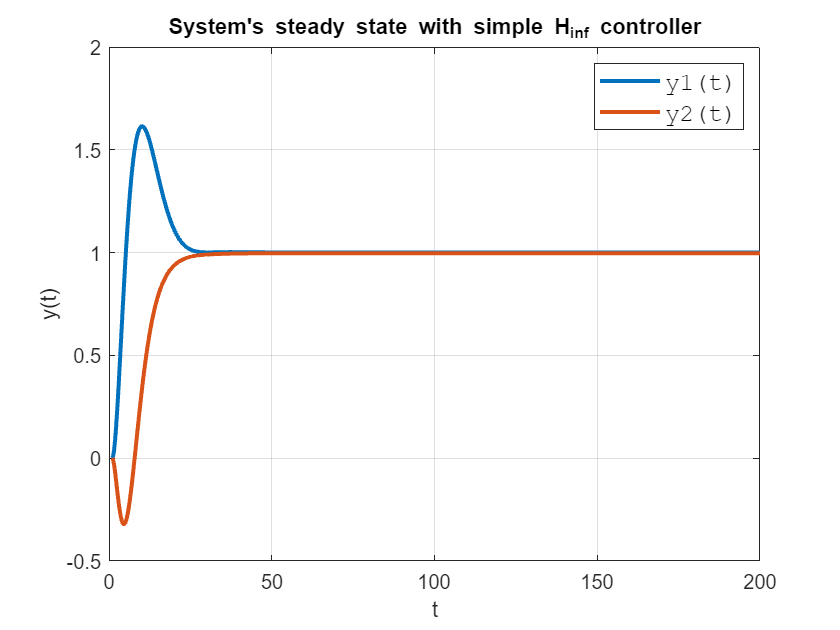

s = tf('s');
A1 = 1E-4;
M1 = 1.5;
omb1 = 2.5;

wp1 = (s/M1+ omb1)/ (s+omb1*A1);
wp = (s/M1+ omb1)/ (s+omb1*A1)* eye(2);    % diagonal weight

[KHinf1, Ghinf1, gopt1] = mixsyn(Gs_nmp, wp, [], []);

Cloop1 = loopsens(Gs_nmp, KHinf1);

r_unit = [ones(length(t),1),ones(length(t),1)];    % dummy reference to check if the controller works

figure()

ycl1 = lsim(Cloop1.To, r_unit, t);
plot(t, ycl1, 'LineWidth', 2), grid
title("System's steady state with simple H_{inf} controller");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','NorthEast')
xlim([0 200]);

The closed loop system is stable.  We can see that the interpolations conditions hold.

%T = (Gs_nmp)/(eye(2)+Gs_nmp);  % inizializing complementary sensitivity matrix
T = Cloop1.To;
S = Cloop1.So;    % inizializing sensitivity matrix

T_z = evalfr(T, zi_nmp(2));    % computing at z = 0.128
S_z = evalfr(S, zi_nmp(2));    % computing at z = 0.128

w_z_nmp(:,1)' * T_z     % showing the limitation

ans = 1.0e-12 *

    0.0780   -0.1353


w_z_nmp(:,1)' * S_z   % showing the limitation

ans =     0.0386   -0.0474


We expect then a NMP zero in  $z_{\textrm{NMP}} =0\ldotp 0128$ in T(s) exhibiting as reasonable the blocking property, exactly like G(s).

So let us solve the generalized eigevectors problem in order to compute the zeros input and output directions, and the zero state directions.

T_sys = ss(T);

GT = [T_sys.A, T_sys.B; T_sys.C, T_sys.D];          % G matrix for T(s)
MT = [eye(14), T_sys.B*0; T_sys.C*0, T_sys.D*0];   % M matrix for T(s)

[nT,zT,mT] = eig(GT,MT)

nT =          0    0.0000    0.0000    0.0000    0.3665   -0.0798    0.1505    0.0000    0.0000    0.0000   -0.2490   -0.0000   -0.0623   -0.0000   -0.0000   -0.0000
         0         0   -0.0000   -0.0000    0.9575   -0.0804    0.0000   -0.7002    0.0000    0.7002    0.0000   -0.0000    0.0000   -0.0009    0.0000    0.0000
         0         0         0   -0.0000   -0.2661   -0.0983   -0.0000    1.0000   -0.0000   -1.0000   -0.0000    0.0000   -0.0000    0.0013    0.0000    0.0000
         0         0    0.0000    0.0000    1.0000    0.0495    0.1155   -0.0000   -0.0000    0.0000   -0.1911   -0.0000   -0.0478   -0.0000   -0.0000   -0.0000
         0         0         0    0.0000   -0.2779    0.0605   -0.1141   -0.0000   -0.0000   -0.0000    0.1887    0.0000    0.0472    0.0000   -0.0000   -0.0000
         0         0    0.0000    0.0000    0.2428    0.0897    0.0000   -0.9125    0.0000    0.9125    0.0000   -0.0000    0.0000   -0.0012   -0.0000   -0.0000
         0   -0.0000   -0.000

zT =        Inf         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0       Inf         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0       Inf         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0       Inf         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0   -0.0562         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.0128         0         0         0         0         0         0         0         0         0         0
         0         0         

mT =     0.0000   -0.0000   -0.0000   -0.0000   -0.7423    0.5369    1.0000    0.3650         0         0         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000    0.3712   -0.2685   -0.4619    0.0633   -0.0000    0.1232   -0.5000    1.0000    0.4513    0.8767   -0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.6526   -0.7138   -0.3826    0.0722   -0.0000    0.1406   -0.4141    0.7002    0.3738    1.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.5000    0.2881   -0.0964    0.5121   -0.9876   -0.0000    0.0482    0.0000    0.5779   -0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.4730    1.0000   -0.1582    1.0000   -1.0000   -0.0000    0.0791    0.0000    0.9481   -0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -1.0000   -0.5762   -0.0648   -0.5314    0.0000    1.0000   -0.0702    0.0000    0.0633    0.4399   -0.0000    0.0000
    0.0000   -0.0000   -0.000

zT(6,6)   % the NMP zeros present also in  G(s)

ans = 0.0128

csi_zT = nT(1:14, 6);    % zero input state directions
v_zT = nT (15:16, 6);   % zero input directions

We can verify the presence of the zero we expected.

All this means that for every controller such that it is able to stabilize the plant G(s) and the resulting closed loop system exhibits the stability property, we will have a blocking NMP zero in 0.0128 In T(s).

Remembering that, in the case of no presence of disturbances or noises,


$$y\left(s\right)=T\left(s\right)\;r\left(s\right)$$


we can state that there will be a lack of control autority with respect to the references of the form $r\left(t\right)=e^{z_2 t} v_{z_2 } \;$and the inizial states  $x\left(0\right)=\xi_z$, sinche the outputs with respect to such references will be identically equal to 0. Let's visualize it with a simulation.

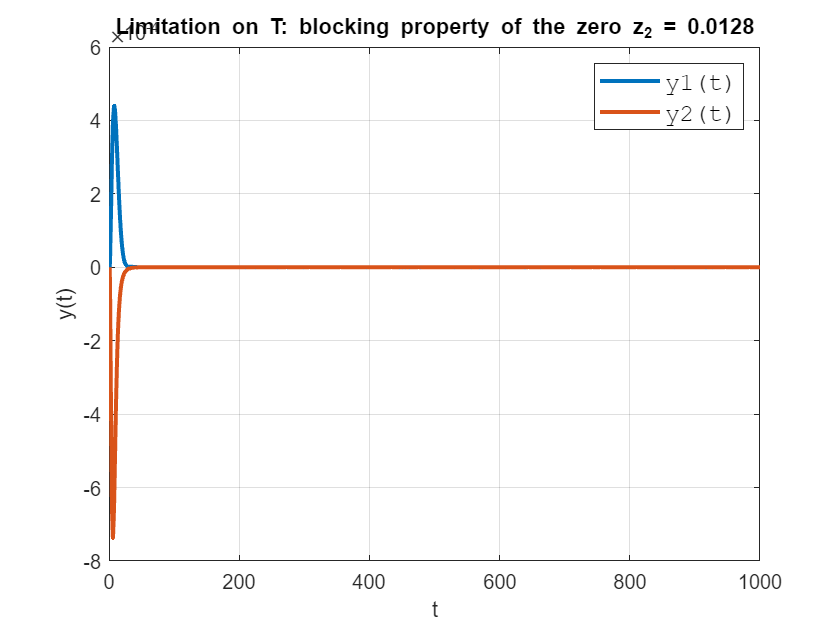


rT = [ones(length(t),1),ones(length(t),1)];   % inizializing the 2 references

for i =1 : length(t)
    rT(i,1) = exp(zi_nmp(2)*t(i))* v_zT(1,1);     % imposing values and directions
    rT(i,2) = exp(zi_nmp(2)*t(i))* v_zT(2,1);
end

y5 = lsim(T_sys,rT,t, csi_zT(1:14));  % outputs

figure()
plot(t, y5, 'LineWidth',2); grid
title("Limitation on T: blocking property of the zero z_{2} = 0.0128");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','NorthEast')

We can see that in such directions the reference can not be reproduced at steady state: the 2 outputs are always identically equal to zero  (except for the problems of approximation that brings initially the outputs to reach values of the order of ${10}^{-4}$).

An additional limitation is derived from the fact that in the SISO  $H_{\infty }$ design we require:


$${\left\|w_p \;\left(s\right)\;S\left(s\right)\right\|}_{\infty } <1$$


In a multivariable context, this is equivalent to require:


$$\max_{\omega } \;|w_p \left(j\omega \right)|\;\bar{\sigma \;|} S\left(j\omega \right)|<1,\;\;\;\;\;i\ldotp e\ldotp \;\;|w_p \left(z\right)|\;<1\;\;\;\;\;\;\;\;\;\textrm{since}\;\;\;\;\;\;\;\;|w_p \left(z\right)|\;<\max_{\omega } \;|w_p \left(j\omega \right)|\;\bar{\sigma \;|} S\left(j\omega \right)|\;$$


where $\bar{\sigma \;} \left(S\right)$ is the largest singular value of S(s).  

SInce  $\;|w_p \left(z\right)|\;=\left|\frac{\frac{z}{M}+\omega_B }{z+\omega_B \;A}\right|\;$,   we obtain an imposition of a bandwith limitation equal to :  $\omega_B <z\;\frac{1-\frac{1}{M}}{1-A}$  in the case of $z$ real, like this case .

So, if we want to require a sensitivity peak to be not more than 2 as usual, and a very small error at steady state (A << 1), we obtain that the bandiwidth can not be greater than $\frac{z}{2}$.

So in our design we have to take into account the fact that   $\omega_B <\frac{0\ldotp 0128}{2}=0\ldotp 0064\ldotp$

We can see from similations that only requiring a bandiwidth below this quantity the MATLAB function mixsyn() is able to find a stabilizing controller coherent with our specifications ($\left.\gamma =1\right)$.

If we try to require more bandiwith than this, we obtain a controller such that again the closed loop bandiwidth for S(s) is not greater than $0\ldotp 0064$, and consequently an higher $\gamma$, increasing as it increases the quantity of bandiwith required. (Remembering that $\gamma$ is an index of how much the resulting controller is far from the point of view of the performances from our initial specifications).

A2 = 1E-4;
M2 = 2;
omb2 = 0.0064;

om = logspace(-2,5,1000);

wp2 = (s/M2+ omb2)/ (s+omb2*A2);
wp22 = (s/M2+ omb2)/ (s+omb2*A2)* eye(2);    % diagonal weight

[KHinf2, Ghinf2, gamma2 gopt2] = mixsyn(Gs_nmp, wp22, [], []);

gamma2     % we have a gamma very close to 1

gamma2 = 1.0040

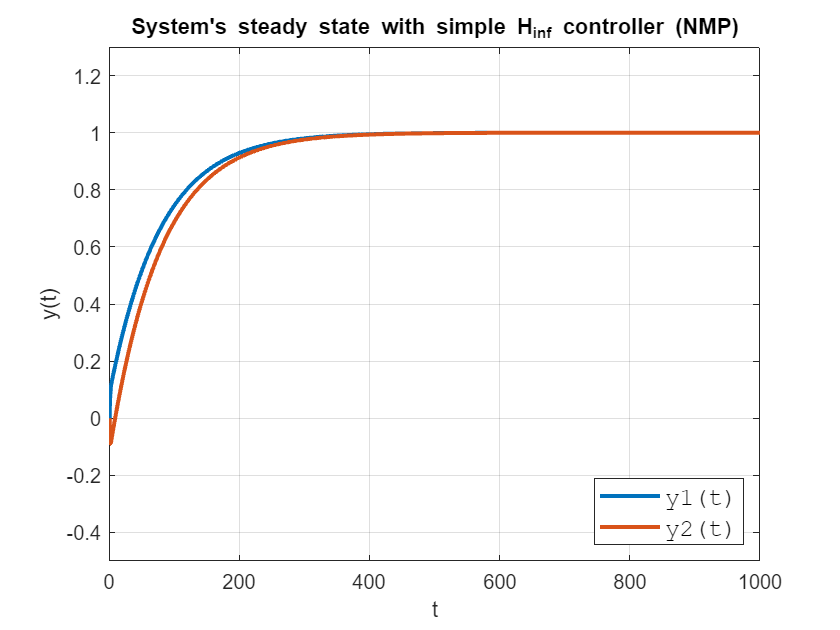

Cloop2 = loopsens(Gs_nmp, KHinf2);

r_unit2 = [ones(length(t),1),ones(length(t),1)];    % dummy reference to check if the controller works

figure()

ycl2 = lsim(Cloop2.To, r_unit2, t);
plot(t, ycl2, 'LineWidth', 2), grid
title("System's steady state with simple H_{inf} controller (NMP)");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')
xlim([0 1000]);
ylim([-0.5 1.3])

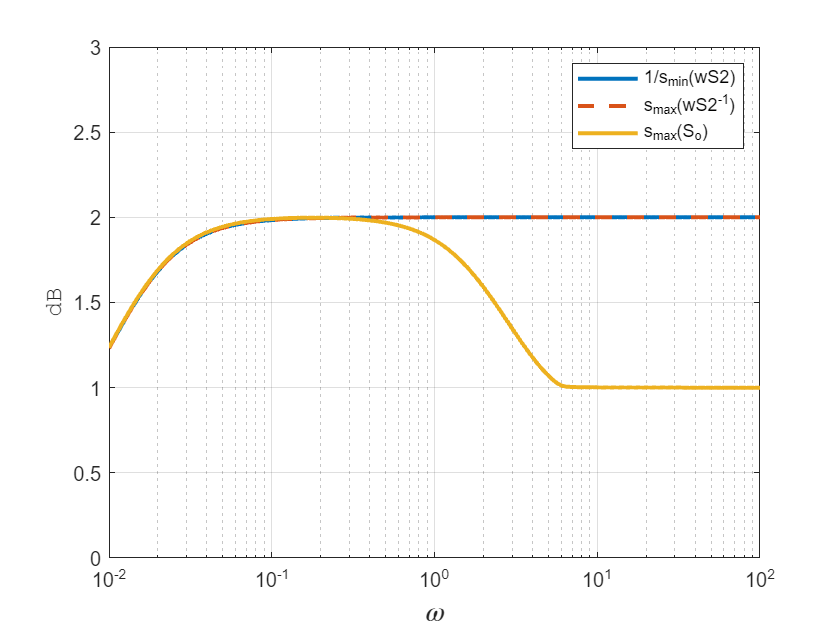

sigmaWS2    = sigma(wp22,om);
sigmaWS2Inv = sigma(1/wp22,om);
sigmaSo2    = sigma(Cloop2.So,om);

figure()
semilogx(om,1./sigmaWS2(2,:),om, sigmaWS2Inv(1,:),'--',...   % plotting the minimum singular value of the weight , the max of the inverted weight, and the max of S(s) 
         om, sigmaSo2(1,:),'LineWidth',2), grid;
legend('1/s_{min}(wS2)','s_{max}(wS2^{-1})','s_{max}(S_o)','Location','northeast');
xlim([1E-2,1E+2]);
ylim([0 3])
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)

We can see that requiring exactly $\omega_B$ = 0.0064 we obtain a controller perfectly coherent with our specifications, such that the maximum singular value of the closed loop sensitivity function S(s) is perfectly upper bounded from the minimum singular value of the designed weight (or of the maximum singular value of the inverse of our weight).

## 4. Robustness Analysis

## Minimum Phase case

Let us now consider some robustness issues, taking as a case of study a situation in which the parameters $\gamma_1 ,\gamma_2 ,k_1 ,k_2$ are uncertain and vary in intervals between +10% and -10% of their nominal value. Initially we start to consider the system G(s) exhibiting Minimum Phase Properties.

NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

% uncertain k_i

k1_mp_u = ureal('K1',3.33,'Range',[(3.33-(3.33/10)), (3.33+(3.33/10))]);   % cm^3/Vs
k2_mp_u = ureal('K2',3.35,'Range',[(3.35-(3.35/10)), (3.35+(3.35/10))]); % cm^3/Vs

% uncertain gamma_i

g1_mp_u =  ureal('G1',0.7,'Range',[(0.7-(0.7/10)), (0.7+(0.7/10))]); 
g2_mp_u = ureal('G2',0.6,'Range',[(0.6-(0.6/10)), (0.6+(0.6/10))]); 

Gs_mp_unc = [(g1_mp_u*k1_mp_u*n1_mp/(1+t1_mp*s)), ((1-g2_mp_u)*k2_mp_u*n1_mp)/ ((1+t3_mp*s)*(1+t1_mp*s)); ((1-g1_mp_u)*k1_mp_u*n2_mp)/ ((1+t2_mp*s)*(1+t4_mp*s)), (g2_mp_u*k2_mp_u*n2_mp)/(1+t2_mp*s)]

Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 6 states.
The model uncertainty consists of the following blocks:
  G1: Uncertain real, nominal = 0.7, range = [0.63,0.77], 2 occurrences
  G2: Uncertain real, nominal = 0.6, range = [0.54,0.66], 2 occurrences
  K1: Uncertain real, nominal = 3.33, range = [3,3.66], 2 occurrences
  K2: Uncertain real, nominal = 3.35, range = [3.02,3.69], 2 occurrences


We want to represent this parametric uncertainty as an unstructured input multiplicative uncertainty of the form:

$G(s) = G_{n}(s)(I_{2x2} + W_m(s)\Delta_m(s))$    with $\| \Delta_m(s)\|_\infty \le 1$ $\forall \omega ,$ and thw weight $W_m \left(s\right)$ such that it satisfy the requirement that:

${\left\|W_m \left(j\omega \right)\right\|}_{\infty } \ge \underset{G_p \in \;\Pi_i }{\sup \;\;}$${\left\|{G_n }^{-1} \left(j\omega \right)\left(G_p j\left(\omega \right)-G_n \left(j\omega \right)\right)\right\|}_{\infty }$, with $\Pi_i$ the set of all possible perturbed plants.

We compute a 3° order  diagonal weight through the command ucover().

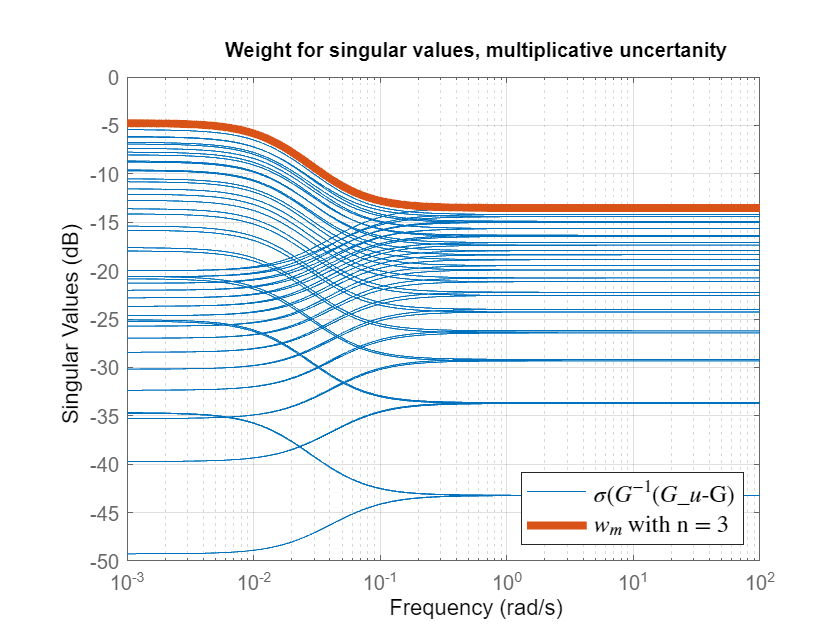

w =logspace (-3,2, 1000);   % frequency span

figure()

Gs_mp_unc_sampled = gridureal(Gs_mp_unc,30);
G_star_mp = inv(Gs_mp)* (Gs_mp_unc_sampled- Gs_mp);  % showing the singular values of the matrix G^-1( G_p - G)
sigma(G_star_mp, w);
hold on;

[PwM1,InfoM1] = ucover(Gs_mp_unc_sampled,Gs_mp,3, 'InputMult');   % computing a suitable weight

[m, p] = bode(InfoM1.W1, w);
plot_weight = semilogx(w, 20*log10(m(1,:)));
set(plot_weight,'LineWidth',4, 'Color',NMatlabRed), grid on;
Leg2 = legend('$\sigma$($G^{-1}$($G_{u}$-G)','$w_m$ with n = 3','Interpreter','latex');
set(Leg2,'FontSize',12,'Location','SouthEast','Interpreter','latex');
grid on;
title('Weight for singular values, multiplicative uncertanity','FontSize',10);

Let us visualize the resulting input multiplicative representation of the uncertainty in terms of relative error:

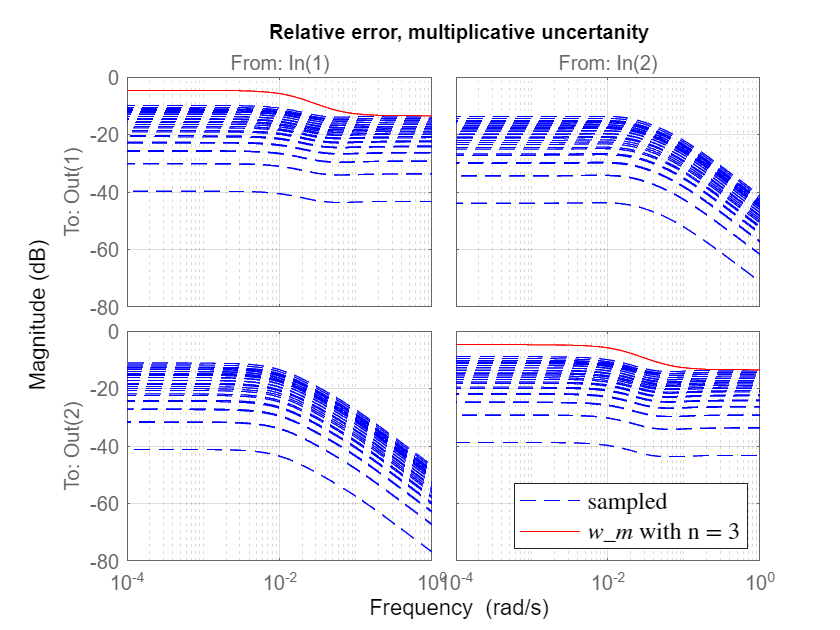

figure()

[PwM1,InfoM1] = ucover(Gs_mp_unc_sampled,Gs_mp,[3 3], 'InputMult');  % choiche of a diagonal weight
Rel_P = (Gs_mp- Gs_mp_unc_sampled )/Gs_mp;   % relative error
bodemag(Rel_P,'b--',InfoM1.W1,'r'), grid on;
Leg2 = legend('sampled','$w_m$ with n = 3','Interpreter','latex');
set(Leg2,'FontSize',12,'Location','SouthEast','Interpreter','latex');
grid on;
title('Relative error, multiplicative uncertanity','FontSize',10);

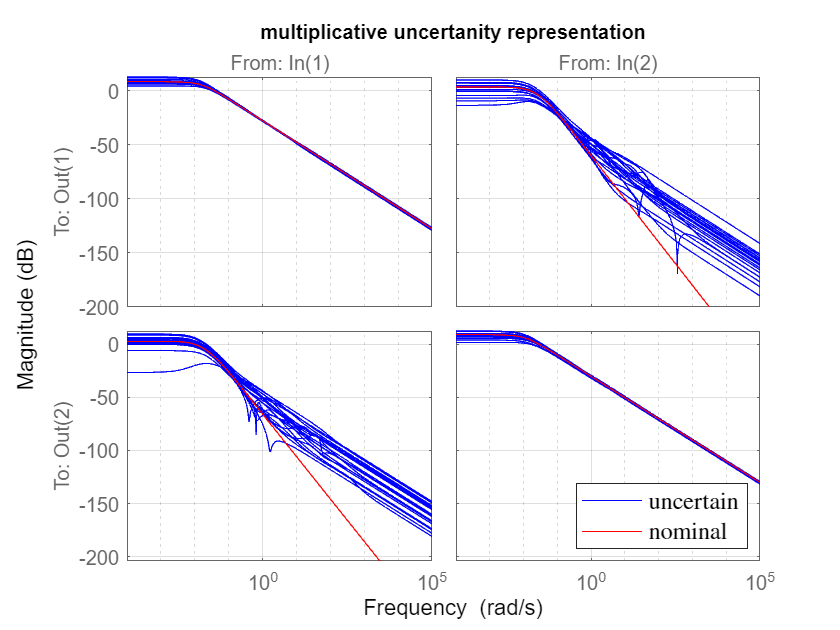

figure
bodemag(PwM1,'b',Gs_mp,'r'), grid on;
Leg2 = legend('uncertain','nominal','Interpreter','latex');
set(Leg2,'FontSize',12,'Location','SouthEast','Interpreter','latex');
grid on
title('multiplicative uncertanity representation','FontSize',10);

We can see from this plots that the most uncertain situation is at low frequency, while at high frequency the diagonal elements of the uncertainty representations are both very close to the nominal process behavior .This result is also highlighted in the Vadigepalli, Gatzke, Doyle's paper.

Let us now compute two different stabilizing decentralized controllers for the nominal case. We want to compare the performance of two different controllers in terms of reference reproduction's capabilities and also in terms of robust stability properties.

The first controller is the decentralized controller PI proposed in the Johansson's paper, the second one is another diagonal controller designed with an $H_{\infty } \;$norm control approach.

% controller for the G(s) with MP property

K1_mp = 3.0;
T1_mp = 30;

K2_mp = 2.7;
T2_mp = 40;

PI1_mp = K1_mp*(1+ (1/(T1_mp*s)));
PI2_mp = K2_mp*(1+ (1/(T2_mp*s)));

PI_mp = [ PI1_mp ,0; 0, PI2_mp]     % decentralized PI controller with Johansson's parameters

PI_mp =
 
  From input 1 to output...
       90 s + 3
   1:  --------
         30 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       108 s + 2.7
   2:  -----------
          40 s
 
Continuous-time transfer function.
Model Properties


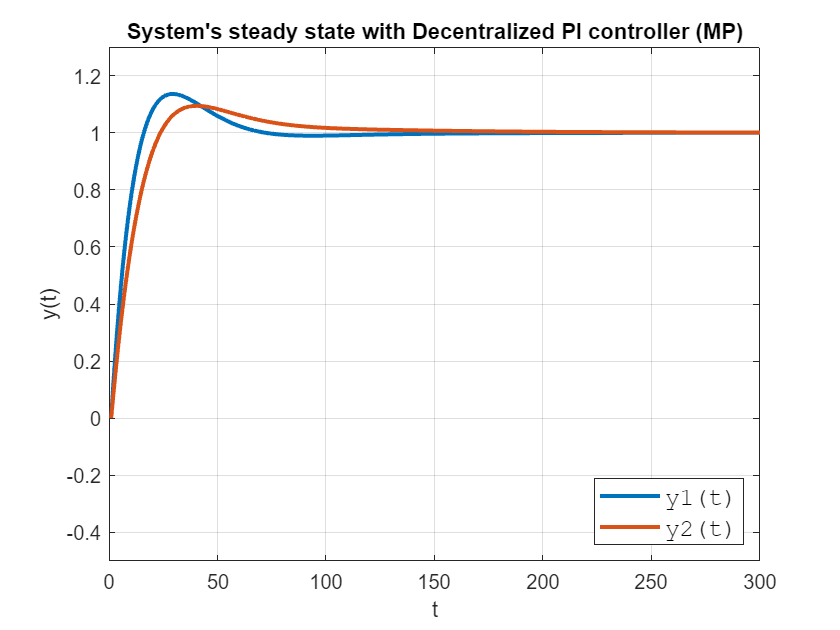

Cloop3 = loopsens(Gs_mp, PI_mp);

r_unit2 = [ones(length(t),1),ones(length(t),1)];   

figure()

ycl3 = lsim(Cloop3.To, r_unit2, t);
plot(t, ycl3, 'LineWidth', 2), grid
title("System's steady state with Decentralized PI controller (MP)");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')
xlim([0 300]);
ylim([-0.5 1.3])

On the other hand, we need for comparison an $H_{\infty } \;$controller for the MP case. We will use the input-output paring derived to be better in the Relative Array Gain analysis:

$\left\lbrack y_1 {\;,\;u}_2 \right\rbrack \;\;,\left\lbrack y_2 {\;,\;u}_1 \right\rbrack \;\;\;$. This implies that the performance weight of the decentralized $H_{\infty } \;$controller will have off-diagonal components $\not= 0$ and the diagonal ones* = 0*.

Since we don't have costraints on the control effort, we just design a weight for the sensitivity function S(s).

A3 = 1E-3;
M3 = 1.2;
omb3 = 0.2;

om = logspace(-2,5,1000);

wp3 = (s/M3+ omb3)/ (s+omb3*A3);
wp33 = (s/M3+ omb3)/ (s+omb3*A3)* [0,1;1,0];    % off-diagonal weight

[KHinf3, Ghinf3, gamma3 gopt2] = mixsyn(Gs_mp, wp33, [], []);

gamma3     % we have a gamma very close to 1

gamma3 = 0.8363

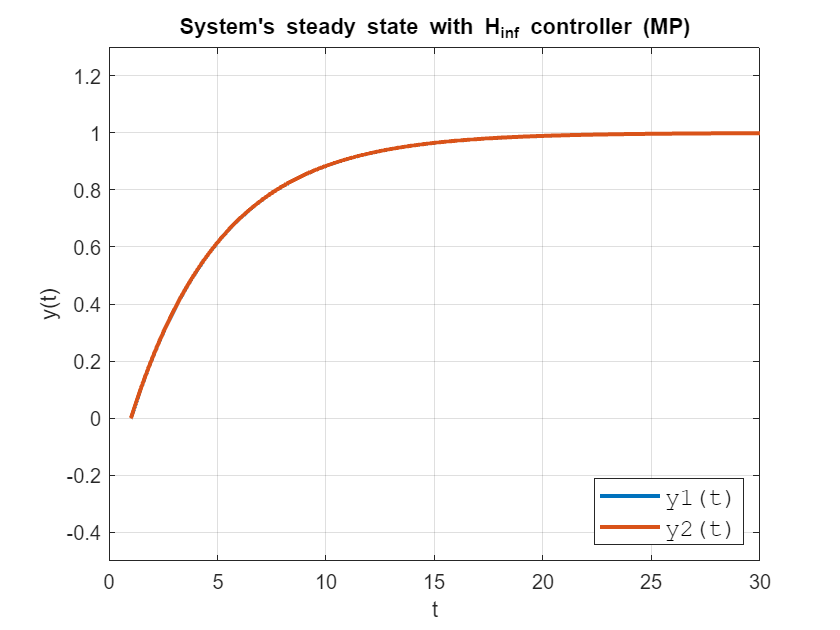

Cloop5 = loopsens(Gs_mp, KHinf3);

figure()

ycl5 = lsim(Cloop5.To, r_unit2, t);
plot(t, ycl5, 'LineWidth', 2), grid
title("System's steady state with H_{inf} controller (MP)");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')
xlim([0 30]);
ylim([-0.5 1.3])

We can see the differences in terms of nominal performance: the $H_{\infty } \;$controller allows a faster transient and not overshoot.

Let us check if this 2 controllers are robust stable, i.e. if they satisfy the necessary and sufficient condition $\|w_m(s)T_{nom}(s)\|_\infty < I$.

L_MP_PI = PI_mp*PwM1;         % open loop function PI
L_MP_Hinf = KHinf3*PwM1;         % open loop function H-infinity

CL_MP_PI = feedback(L_MP_PI, eye(2));              % closed loop function PI
CL_MP_Hinf= feedback(L_MP_Hinf, eye(2));   % closed loop function H-infinity

[stabmarg1,wcu1]   = robstab(CL_MP_PI) 

stabmarg1 = struct with fields:
           LowerBound: 1.7088
           UpperBound: 1.7123
    CriticalFrequency: 1.0000e-04


wcu1 = struct with fields:
    Gs_mp_unc_sampled_InputMultDelta: [2×2 ss]


[stabmarg2,wcu2]   = robstab(CL_MP_Hinf) 

stabmarg2 = struct with fields:
           LowerBound: 1.7102
           UpperBound: 1.7137
    CriticalFrequency: 1.0000e-04


wcu2 = struct with fields:
    Gs_mp_unc_sampled_InputMultDelta: [2×2 ss]


Being the upper and lower bounds striclty >1 in both case, we can state that both controllers are able to robust stabilize the uncertain system with MP property.

Let us check if they can also guarantee robust performance, i.d. if $\;\underset{\omega }{\sup \;\;}$$\mu_{\Delta f\;} \left(M\left(j\omega \right)\right)$   where $M$ is the $N_{11}$ component of the augmented plant $F_e \left(P,C\right),$ the only possible source of instability of the overall control structured system $F_u \;\left(N,\Delta \right),\;$and $\mu_{\Delta f}$ is the structured singular value.

[perfmarg_MP_Hinf,wcu,report,info1] = robustperf(CL_MP_Hinf)

perfmarg_MP_Hinf = struct with fields:
           LowerBound: 0.9642
           UpperBound: 0.9643
    CriticalFrequency: 0.0310


wcu = struct with fields:
    Gs_mp_unc_sampled_InputMultDelta: [2×2 ss]


report = 5×129 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                                 '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 96.4% of the modeled uncertainty.                '
    ' -- A model uncertainty of 96.4% can lead to input/output gain of 1.04 at 0.031 rad/seconds.                                     '
    ' -- Sensitivity with respect to each uncertain element is:                                                                       '
    '      13% for Gs_mp_unc_sampled_InputMultDelta. Increasing Gs_mp_unc_sampled_InputMultDelta by 25% decreases the margin by 3.25%.'


info1 = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [113×1 double]
    BadUncertainValues: [113×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]


[perfmarg_MP_PI,wcu,report,info2] = robustperf(CL_MP_PI)

perfmarg_MP_PI = struct with fields:
           LowerBound: 0.8010
           UpperBound: 0.8022
    CriticalFrequency: 0.0567


wcu = struct with fields:
    Gs_mp_unc_sampled_InputMultDelta: [2×2 ss]


report = 5×129 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                                 '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 80.1% of the modeled uncertainty.                '
    ' -- A model uncertainty of 80.2% can lead to input/output gain of 1.25 at 0.0567 rad/seconds.                                    '
    ' -- Sensitivity with respect to each uncertain element is:                                                                       '
    '      15% for Gs_mp_unc_sampled_InputMultDelta. Increasing Gs_mp_unc_sampled_InputMultDelta by 25% decreases the margin by 3.75%.'


info2 = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [69×1 double]
    BadUncertainValues: [69×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]


While we had robust stability for both control systems, we don't have robust performance capabilities, being the lower and the upper bounds for robust performance strictly <1 in both cases.

Let us visualize how the structured singulare value varies with variation of frequencies.

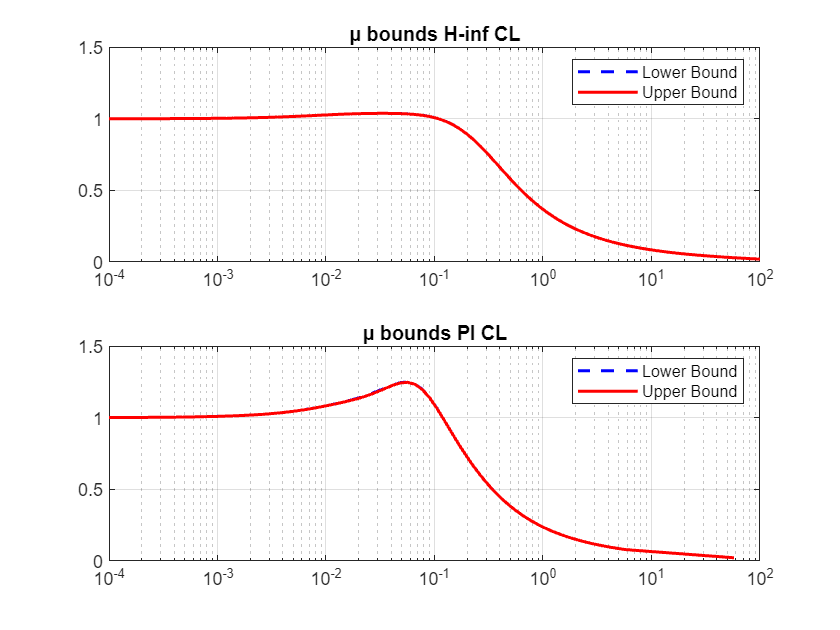

% extracting the values for the H inf controller

a = info1.MussvBnds(1,1);  
 b = info1.MussvBnds(1,2);
 
 max_mp_Hinf = zeros(length(info1.Frequency),1);
 for i=1:size(info1.Frequency)
     max_mp_Hinf(i)= a.Response(:,:,i);
 end
min_mp_Hinf = zeros(length(info1.Frequency),1);
 for i=1:length(info1.Frequency)
     min_mp_Hinf(i)= b.Response(:,:,i);
 end

 % extracting the values for the PI controller

 c = info2.MussvBnds(1,1);
 d = info2.MussvBnds(1,2);
 
 max_mp_PI = zeros(length(info2.Frequency),1);
 for i=1:length(info2.Frequency)
     max_mp_PI(i)= c.Response(:,:,i);
 end
 min_mp_PI = zeros(length(info2.Frequency),1);
 for i=1:length(info2.Frequency)
     min_mp_PI(i)= d.Response(:,:,i);
 end

figure()

subplot(211)
semilogx(info1.Frequency, max_mp_Hinf,'b--',info1.Frequency, min_mp_Hinf,'r-','LineWidth',1.5);
legend('Lower Bound','Upper Bound');
title('µ bounds H-inf CL');
xlim([1.e-4,1.e+2])
ylim([0,1.5])
grid on;

subplot(212)
semilogx(info2.Frequency, max_mp_PI,'b--',info2.Frequency, min_mp_PI,'r-','LineWidth',1.5);
legend('Lower Bound','Upper Bound');
title('µ bounds PI CL');
ylim([0,1.5])
xlim([1.e-4,1.e+2])
grid on;

This plot confirms our expectations: both controllers can not achieve robust performance since the structured singular value is >1 for some $\omega$, but we can see that the $H_{\infty } \;$one is significantly closer to achieve RP: the upper and lower bounds are higher than the ones of the PI closed loop and also the condition $\mu_{\Delta f}$ < 1 is vialoted at very few frequencies.

Let us try to design a $H_{\infty } \;$ controller able to guarantee robust performance trhough $\mu$-synthesis control.

We have to build the augumented plant and run the D-K algorithm.

opts = hinfsynOptions;
opts.Display = 'on';

% weights for S(s)

A4 = 1E-2;
M4 = 1.28;
omb4 = 40;

wp44 = ((s/M4+ omb4)/ (s+omb4*A4))* [0,1;1,0];    % off diagonal weight

 % inizializing the inputs and the outputs of each block

PwM1.u = 'u';                       % control input
PwM1.y = 'y';                       % not perturbed output
wp44.u = 'v';
wp44.y = 'z';                   % performance variable

Sum3 = sumblk('v = r - y', 2);     % measured variables

Pe_MP = connect(PwM1,wp44,Sum3, {'r','u'},{'z','v' });   % augmented plant

ncont = 2; % two control inputs
nmeas = 2; % two measurements
[Krob1,rpMU1] = musyn(Pe_MP ,nmeas,ncont)



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           30.04        30.04        30.28             8
    2           10.88        10.88        10.88             8
    3           3.278        2.964        2.983            20
    4           2.784        1.797        1.807            12
    5           1.704        1.454         1.46            12
    6           1.422        1.301        1.306            12
    7            1.28        1.204        1.212            20
    8             1.2        1.144        1.153            20
    9           1.135        1.094        1.103            20
   10            1.08         1.05        1.059            20

Best achieved robust performance: 1.05


Krob1 =
 
  A = 
                x1          x2      

rpMU1 = 1.0502

After 10 iterations, the best attempt of musyn() using D-K algorithm ends with a ${20}^{\textrm{th}}$order controller able to guarantee a maximum structured singular value of 1.052, so not robust performant in absolute terms, but very close.

 We expect lower and upper bounds for robust performance indices very close to one.

L_MP_rob = Krob1*PwM1;         % open loop function robust performance controller (MP)

CL_MP_rob = feedback(L_MP_rob, eye(2));              % closed loop robust performance controller (MP)

[perfmarg_MP_rob,wcu,report,info3] = robustperf(CL_MP_rob)

perfmarg_MP_rob = struct with fields:
           LowerBound: 0.9805
           UpperBound: 0.9806
    CriticalFrequency: 12.3801


wcu = struct with fields:
    Gs_mp_unc_sampled_InputMultDelta: [2×2 ss]


report = 5×128 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                                '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 98.1% of the modeled uncertainty.               '
    ' -- A model uncertainty of 98.1% can lead to input/output gain of 1.02 at 12.4 rad/seconds.                                     '
    ' -- Sensitivity with respect to each uncertain element is:                                                                      '
    '      14% for Gs_mp_unc_sampled_InputMultDelta. Increasing Gs_mp_unc_sampled_InputMultDelta by 25% decreases the margin by 3.5%.'


info3 = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [121×1 double]
    BadUncertainValues: [121×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]


Let us visualize the behavior of the structured singular value in a suitable range of frequencies.

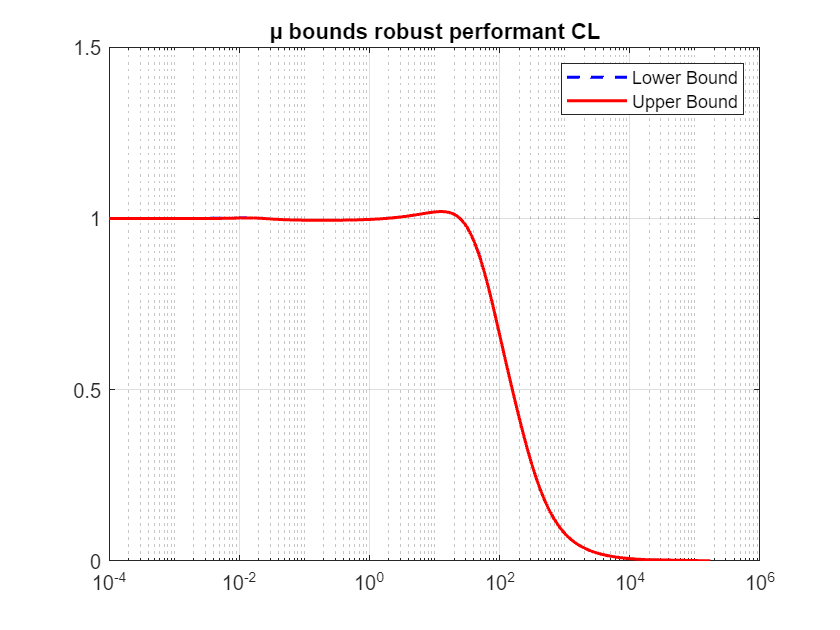

 % extracting the structured singular values for the µ-syn robust controller

p = info3.MussvBnds(1,1);
o = info3.MussvBnds(1,2);
 
 max_mp_rob = zeros(length(info3.Frequency),1);

 for i=1:length(info3.Frequency)
     max_mp_rob(i)= p.Response(:,:,i);
 end

 min_mp_rob = zeros(length(info3.Frequency),1);

 for i=1:length(info3.Frequency)
     min_mp_rob(i)= o.Response(:,:,i);
 end

figure()

semilogx(info3.Frequency, max_mp_rob,'b--',info3.Frequency, min_mp_rob,'r-','LineWidth',1.5);
legend('Lower Bound','Upper Bound');
title('µ bounds robust performant CL');
xlim([1.e-4,1.e+6])
ylim([0,1.5])
grid on;

We can see that µ is always <1 exept for a small neighborood of the critical frequency $\omega^* =12\ldotp 38\;\textrm{Hz}$. This result is reasonably the best achieved in terms of robust performance,

better  than the $H_{\infty } \;$nominal controller which achieves a robust performance index around 96.42%, and than the PI that achieves about 80%.

Let us compute the step response and try to visualize some possible behaviors (20) of closed loop system under the µ-syn controller.

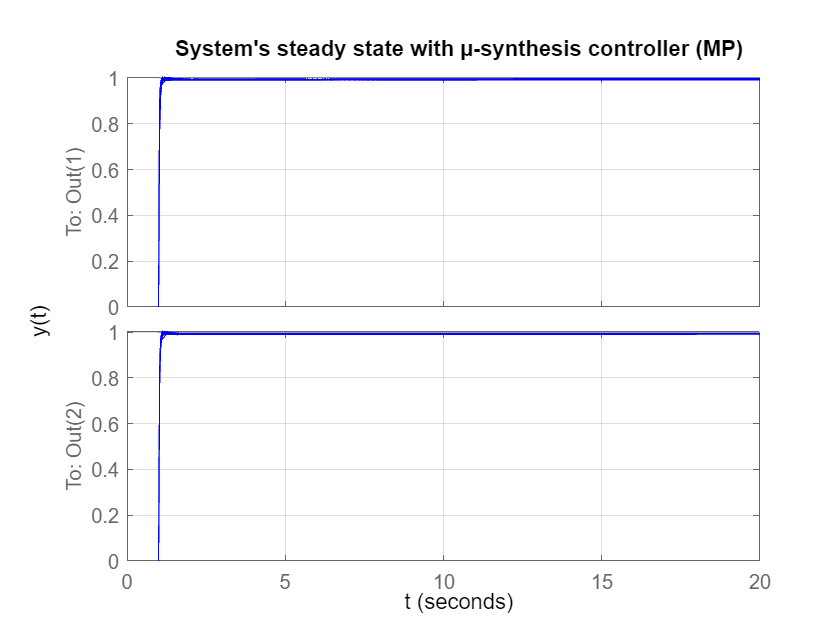

L_MP_rob = Krob1* PwM1;     % robust open loop
CL_MP_rob = feedback(L_MP_rob, eye(2));  % robust closed loop

figure()
samples_MP = usample(CL_MP_rob ,20);
lsim(samples_MP , 'b',r_unit2, t);
title("System's steady state with µ-synthesis controller (MP)");
xlabel("t");
ylabel("y(t)");
xlim([0 20]);
grid on;

## Non-Minimum Phase case

% uncertain k_i

k1_nmp_u = ureal('K1',3.14,'Range',[(3.14-(3.14/10)), (3.14+(3.14/10))]);   % cm^3/Vs
k2_nmp_u = ureal('K2',3.29,'Range',[(3.29-(3.29/10)), (3.29+(3.29/10))]); % cm^3/Vs

% uncertain gamma_i

g1_nmp_u =  ureal('G1',0.43,'Range',[(0.43-(0.43/10)), (0.43+(0.43/10))]); 
g2_nmp_u = ureal('G2',0.34,'Range',[(0.34-(0.34/10)), (0.34+(0.34/10))]); 

Gs_nmp_unc = [(g1_nmp_u*k1_nmp_u*n1_nmp/(1+t1_nmp*s)), ((1-g2_nmp_u)*k2_nmp_u*n1_nmp)/ ((1+t3_nmp*s)*(1+t1_nmp*s)); ((1-g1_nmp_u)*k1_nmp_u*n2_nmp)/ ((1+t2_nmp*s)*(1+t4_nmp*s)), (g2_nmp_u*k2_nmp_u*n2_nmp)/(1+t2_nmp*s)]

Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 6 states.
The model uncertainty consists of the following blocks:
  G1: Uncertain real, nominal = 0.43, range = [0.387,0.473], 2 occurrences
  G2: Uncertain real, nominal = 0.34, range = [0.306,0.374], 2 occurrences
  K1: Uncertain real, nominal = 3.14, range = [2.83,3.45], 2 occurrences
  K2: Uncertain real, nominal = 3.29, range = [2.96,3.62], 2 occurrences


We want to represent this parametric uncertainty as an unstructured input multiplicative uncertainty of the form:

$G(s) = G_{n}(s)(I_{2x2} + W_m(s)\Delta_m(s))$    with $\| \Delta_m(s)\|_\infty \le 1$ $\forall \omega ,$ and thw weight $W_m \left(s\right)$ such that it satisfy the requirement that:

${\left\|W_m \left(j\omega \right)\right\|}_{\infty } \ge \underset{G_p \in \;\Pi_i }{\sup \;\;}$${\left\|{G_n }^{-1} \left(j\omega \right)\left(G_p j\left(\omega \right)-G_n \left(j\omega \right)\right)\right\|}_{\infty }$, with $\Pi_i$ the set of all possible perturbed plants.

We compute a 3° order  diagonal weight through the command ucover().

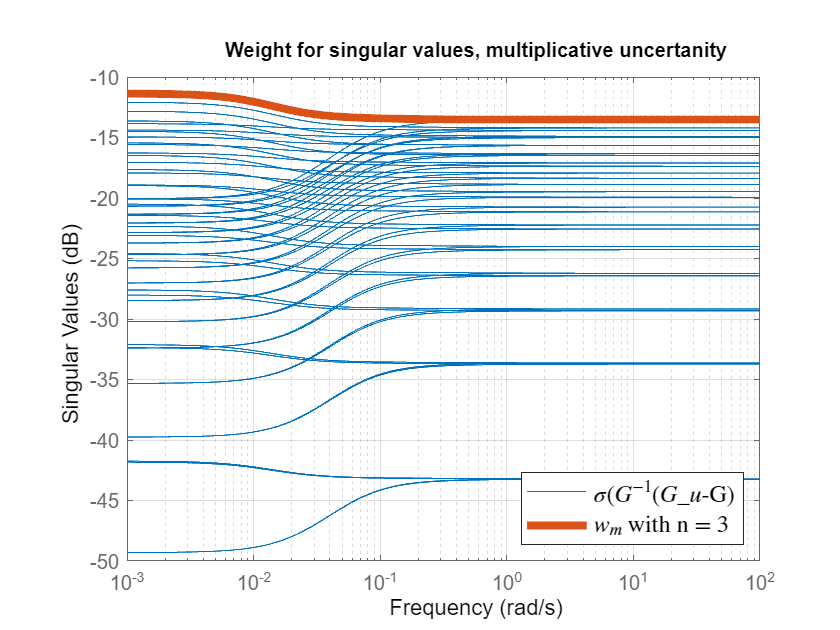

w =logspace (-3,2, 1000);   % frequency span

figure()

Gs_nmp_unc_sampled = gridureal(Gs_nmp_unc,30);
G_star_nmp = inv(Gs_nmp)* (Gs_nmp_unc_sampled- Gs_nmp);  % showing the singular values of the matrix G^-1( G_p - G)
sigma(G_star_nmp, w);
hold on;

[PwM2,InfoM2] = ucover(Gs_nmp_unc_sampled,Gs_nmp,3, 'InputMult');   % computing a suitable weight

[m, p] = bode(InfoM2.W1, w);
plot_weight = semilogx(w, 20*log10(m(1,:)));
set(plot_weight,'LineWidth',4, 'Color',NMatlabRed), grid on;
Leg2 = legend('$\sigma$($G^{-1}$($G_{u}$-G)','$w_m$ with n = 3','Interpreter','latex');
set(Leg2,'FontSize',12,'Location','SouthEast','Interpreter','latex');
grid on;
title('Weight for singular values, multiplicative uncertanity','FontSize',10);

Let us visualize the resulting input multiplicative representation of the uncertainty in terms of relative error:

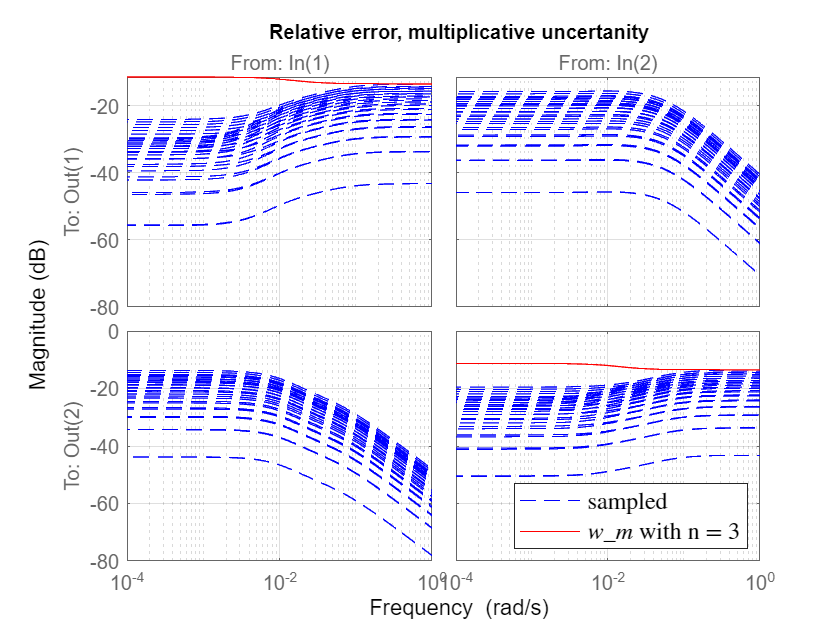

figure()

[PwM2,InfoM2] = ucover(Gs_nmp_unc_sampled,Gs_nmp,[3 3], 'InputMult');  % choiche of a diagonal weight
Rel_P = (Gs_nmp- Gs_nmp_unc_sampled )/Gs_nmp;   % relative error
bodemag(Rel_P,'b--',InfoM2.W1,'r'), grid on;
Leg2 = legend('sampled','$w_m$ with n = 3','Interpreter','latex');
set(Leg2,'FontSize',12,'Location','SouthEast','Interpreter','latex');
grid on;
title('Relative error, multiplicative uncertanity','FontSize',10);

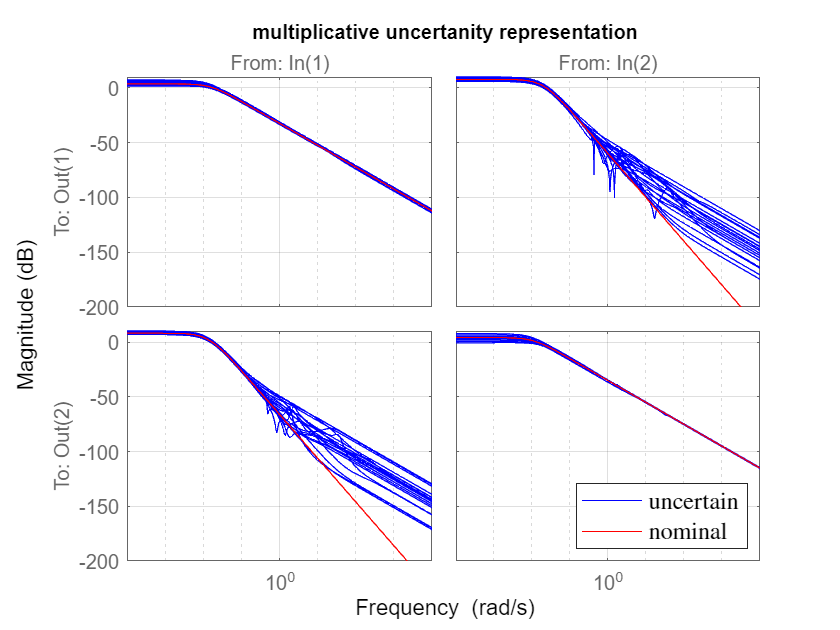

figure
bodemag(PwM2,'b',Gs_nmp,'r'), grid on;
Leg2 = legend('uncertain','nominal','Interpreter','latex');
set(Leg2,'FontSize',12,'Location','SouthEast','Interpreter','latex');
grid on
title('multiplicative uncertanity representation','FontSize',10);

We can see from this plots that the most uncertain situation is at low frequency, while at high frequency the diagonal elements of the uncertainty representations are both very close to the nominal process behavior .This result is also highlighted in the Vadigepalli, Gatzke, Doyle's paper.

Let us now compute two different stabilizing decentralized controllers for the nominal case. 

The first controller is the decentralized controller PI proposed in the Johansson's paper, the second one is another diagonal controller designed with an $H_{\infty } \;$norm control approach.

% controller for the G(s) with NMP property

K1_nmp = 1.5;
T1_nmp = 110;

K2_nmp = -0.12;
T2_nmp = 220;

PI1_nmp = K1_nmp*(1+ (1/(T1_nmp*s)));
PI2_nmp = K2_nmp*(1+ (1/(T2_nmp*s)));

PI_nmp = [PI1_nmp, 0;  0,PI2_nmp]       % decentralized PI controller with Johansson's parameters

PI_nmp =
 
  From input 1 to output...
       165 s + 1.5
   1:  -----------
          110 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       -26.4 s - 0.12
   2:  --------------
           220 s
 
Continuous-time transfer function.
Model Properties


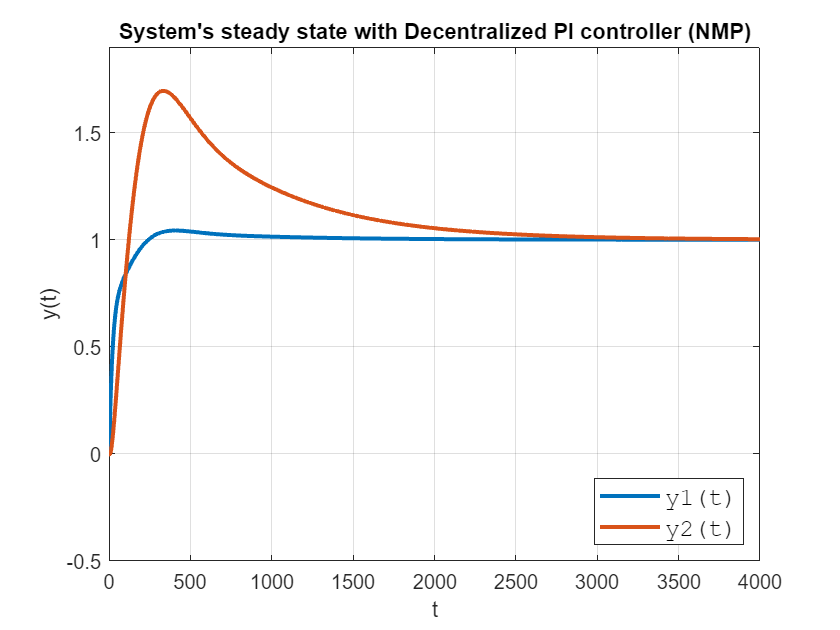


Cloop4 = loopsens(Gs_nmp, PI_nmp);
t_nmp = 1:0.001:4000;   % inizializing the time span for the non minimum phase transient!
r_unit3 = [ones(length(t_nmp),1),ones(length(t_nmp),1)];

figure()

ycl4 = lsim(Cloop4.To, r_unit3, t_nmp);
plot(t_nmp, ycl4, 'LineWidth', 2), grid
title("System's steady state with Decentralized PI controller (NMP)");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')
xlim([0 4000]);
ylim([-0.5 1.9])

Note the difference in terms of time scale: the PI controller produces an output of the system with NMP property with a transient about 10 times slower than in the MP case.

For the $H_{\infty } \;$controller we can use the one designed in the previous section for the NMP case, the one that takes into account the bandwith limitations imposed by the presence of the $\textrm{Re}\left\lbrack \;\right\rbrack >0$ transmittion zero. 

%weight selection
A7 = 1E-4;
M7 = 2;
omb7 = 0.0064;


om = logspace(-2,5,1000);

wp55 = (s/M7+ omb7)/ (s+omb7*A7)* [0,1;1,0];    % off-diagonal weight

[KHinf7, Ghinf7, gamma7, gopt7] = mixsyn(Gs_nmp, wp55, [], []);

gamma7     % we have a gamma very close to 1

gamma7 = 1.0040

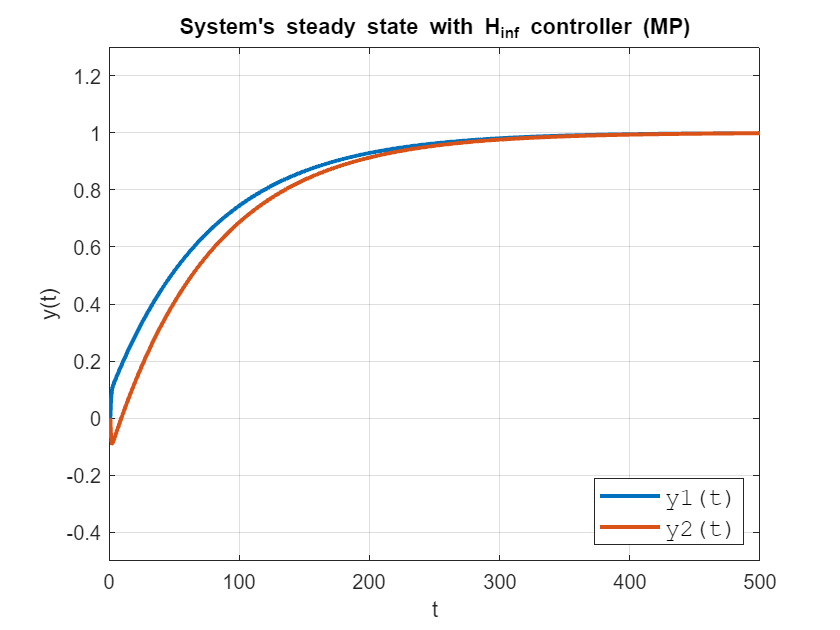

Cloop7 = loopsens(Gs_nmp, KHinf7);

figure()

ycl7 = lsim(Cloop7.To, r_unit2, t);
plot(t, ycl7, 'LineWidth', 2), grid
title("System's steady state with H_{inf} controller (MP)");
xlabel("t");
ylabel("y(t)");
legend('y1(t)','y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')
xlim([0 500]);
ylim([-0.5 1.3])

We can see the differences in terms of nominal performance: the $H_{\infty } \;$controller allows a faster transient and not overshoot.

In both situations the outputs are slower than the corresponding MP case of about a order of magnitude.

Let us check if this 2 controllers are robust stable, i.e. if they satisfy the necessary and sufficient condition $\|w_m(s)T_{nom}(s)\|_\infty < I$.

L_NMP_PI = PI_nmp*PwM2;         % open loop function PI
L_NMP_Hinf = KHinf7*PwM2;         % open loop function H-infinity

CL_NMP_PI = feedback(L_NMP_PI, eye(2));              % closed loop function PI
CL_NMP_Hinf= feedback(L_NMP_Hinf, eye(2));   % closed loop function H-infinity

[stabmarg1,wcu1]   = robstab(CL_NMP_PI) 

stabmarg1 = struct with fields:
           LowerBound: 1.7651
           UpperBound: 1.7687
    CriticalFrequency: 0.0052


wcu1 = struct with fields:
    Gs_nmp_unc_sampled_InputMultDelta: [2×2 ss]


[stabmarg2,wcu2]   = robstab(CL_NMP_Hinf) 

stabmarg2 = struct with fields:
           LowerBound: 3.6340
           UpperBound: 3.6413
    CriticalFrequency: 8.9079e-04


wcu2 = struct with fields:
    Gs_nmp_unc_sampled_InputMultDelta: [2×2 ss]


Being the upper and lower bounds striclty >1 in both case, we can state that both controllers are able to robust stabilize the uncertain system with MP property.

Let us check if they can also guarantee robust performance, i.d. if $\;\underset{\omega }{\sup \;\;}$$\mu_{\Delta f\;} \left(M\left(j\omega \right)\right)$   where $M$ is the $N_{11}$ component of the augmented plant $F_e \left(P,C\right),$ the only possible source of instability of the overall control structured system $F_u \;\left(N,\Delta \right),\;$and $\mu_{\Delta f}$ is the structured singular value.

[perfmarg_MP_Hinf,wcu,report,info1] = robustperf(CL_NMP_Hinf)

perfmarg_MP_Hinf = struct with fields:
           LowerBound: 0.6966
           UpperBound: 0.6966
    CriticalFrequency: 0.0647


wcu = struct with fields:
    Gs_nmp_unc_sampled_InputMultDelta: [2×2 ss]


report = 5×131 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                                   '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 69.7% of the modeled uncertainty.                  '
    ' -- A model uncertainty of 69.7% can lead to input/output gain of 1.44 at 0.0647 rad/seconds.                                      '
    ' -- Sensitivity with respect to each uncertain element is:                                                                         '
    '      23% for Gs_nmp_unc_sampled_InputMultDelta. Increasing Gs_nmp_unc_sampled_InputMultDelta by 25% decreases the margin by 5.75%.'


info1 = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [100×1 double]
    BadUncertainValues: [100×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]


[perfmarg_MP_PI,wcu,report,info2] = robustperf(CL_NMP_PI)

perfmarg_MP_PI = struct with fields:
           LowerBound: 0.3708
           UpperBound: 0.3709
    CriticalFrequency: 0.0066


wcu = struct with fields:
    Gs_nmp_unc_sampled_InputMultDelta: [2×2 ss]


report = 5×128 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                                '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 37.1% of the modeled uncertainty.               '
    ' -- A model uncertainty of 37.1% can lead to input/output gain of 2.7 at 0.00658 rad/seconds.                                   '
    ' -- Sensitivity with respect to each uncertain element is:                                                                      '
    '      20% for Gs_nmp_unc_sampled_InputMultDelta. Increasing Gs_nmp_unc_sampled_InputMultDelta by 25% decreases the margin by 5%.'


info2 = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [87×1 double]
    BadUncertainValues: [87×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]


As in the MP case, while we had robust stability for both control systems, we don't have robust performance capabilities, being the lower and the upper bounds for robust performance strictly <1 in both cases.

Let us visualize how the structured singulare value varies with variation of frequencies.

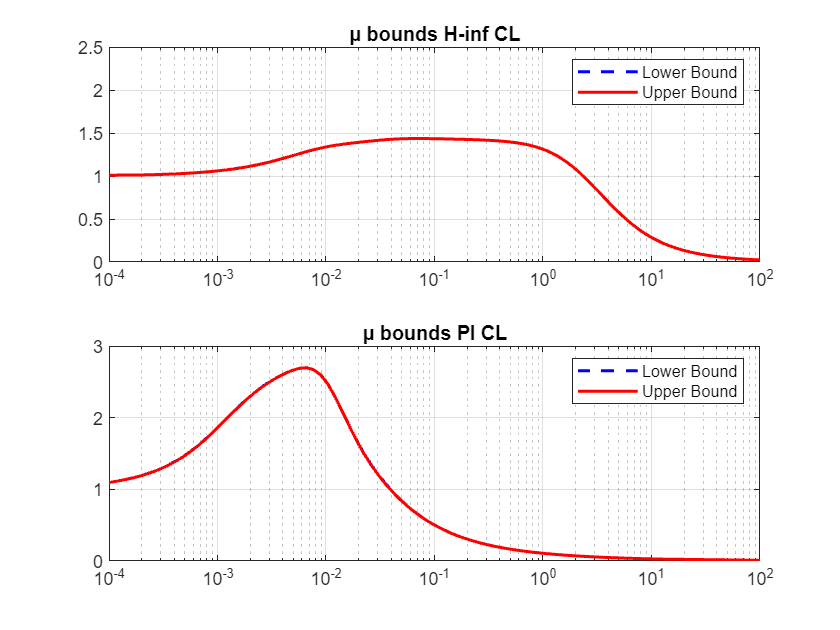

% extracting the values for the H inf controller

a = info1.MussvBnds(1,1);  
b = info1.MussvBnds(1,2);
 
 max_nmp_Hinf = zeros(length(info1.Frequency),1);
 for i=1:size(info1.Frequency)
     max_nmp_Hinf(i)= a.Response(:,:,i);
 end
min_nmp_Hinf = zeros(length(info1.Frequency),1);
 for i=1:length(info1.Frequency)
     min_nmp_Hinf(i)= b.Response(:,:,i);
 end

 % extracting the values for the PI controller

 c = info2.MussvBnds(1,1);
 d = info2.MussvBnds(1,2);
 
 max_nmp_PI = zeros(length(info2.Frequency),1);
 for i=1:length(info2.Frequency)
     max_nmp_PI(i)= c.Response(:,:,i);
 end
 min_nmp_PI = zeros(length(info2.Frequency),1);
 for i=1:length(info2.Frequency)
     min_nmp_PI(i)= d.Response(:,:,i);
 end

figure()

subplot(211)
semilogx(info1.Frequency, max_nmp_Hinf,'b--',info1.Frequency, min_nmp_Hinf,'r-','LineWidth',1.5);
legend('Lower Bound','Upper Bound');
title('µ bounds H-inf CL');
xlim([1.e-4,1.e+2])
ylim([0,2.5])
grid on;

subplot(212)
semilogx(info2.Frequency, max_nmp_PI,'b--',info2.Frequency, min_nmp_PI,'r-','LineWidth',1.5);
legend('Lower Bound','Upper Bound');
title('µ bounds PI CL');
ylim([0,3])
xlim([1.e-4,1.e+2])
grid on;

Here we have another important limitation of the NMP case: the robust performance condition is much more violated by both controllers than the MP case. Anyaway the $H_{\infty } \;$again looks like to behave better than the PI.

Let us try to design a $H_{\infty } \;$ controller able to guarantee robust performance trhough $\mu$-synthesis control.

We have to build the augumented plant and run the D-K algorithm: the requirements on the weights have to be coherent with the limitations imposed by the NMP property of the system.

opts = hinfsynOptions;
opts.Display = 'on';

% weights for S(s)

A8 = 1E-1;
M8 = 2;
omb8 = 0.0064;    % maximal bandiwith allowed for NMP zero

wp66 = ((s/M8+ omb8)/ (s+omb8*A8))* [0,1;1,0];    % off diagonal weight

 % inizializing the inputs and the outputs of each block

PwM2.u = 'u';                       % control input
PwM2.y = 'y';                       % not perturbed output
wp66.u = 'v';
wp66.y = 'z';                   % performance variable

Sum4 = sumblk('v = r - y', 2);     % measured variables

Pe_NMP = connect(PwM2,wp66,Sum4, {'r','u'},{'z','v' });   % augmented plant

ncont = 2; % two control inputs
nmeas = 2; % two measurements
[Krob2,rpMU2] = musyn(Pe_NMP ,nmeas,ncont)



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           1.522        1.391        1.405             4
    2           1.265        1.222        1.234            12
    3           1.206         1.19        1.202            12
    4           1.199        1.186        1.198            12
    5             1.2        1.188          1.2            12

Best achieved robust performance: 1.19


Krob2 =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26
   x1     -0.01107        0

rpMU2 = 1.1862

After only 5 iterations, the best attempt of musyn() using D-K algorithm ends with a ${12}^{\textrm{th}}$order controller able to guarantee a maximum structured singular value of 1.18, so not robust performant. Also the attempt of relaxing the requirements in the weight selections parameters is not sufficient to achieve better performances: we accepted also 1% of steady state error and an maximal overshoot of 2.

 We expect lower and upper bounds for robust performance indices significantly lower than the MP case.

L_NMP_rob = Krob2*PwM2;         % open loop function robust performance controller (MP)

CL_NMP_rob = feedback(L_NMP_rob, eye(2));              % closed loop robust performance controller (MP)

[perfmarg_NMP_rob,wcu,report,info4] = robustperf(CL_NMP_rob)

perfmarg_NMP_rob = struct with fields:
           LowerBound: 0.7627
           UpperBound: 0.7627
    CriticalFrequency: 0.0875


wcu = struct with fields:
    Gs_nmp_unc_sampled_InputMultDelta: [2×2 ss]


report = 5×128 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                                '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 76.3% of the modeled uncertainty.               '
    ' -- A model uncertainty of 76.3% can lead to input/output gain of 1.31 at 0.0875 rad/seconds.                                   '
    ' -- Sensitivity with respect to each uncertain element is:                                                                      '
    '      24% for Gs_nmp_unc_sampled_InputMultDelta. Increasing Gs_nmp_unc_sampled_InputMultDelta by 25% decreases the margin by 6%.'


info4 = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [89×1 double]
    BadUncertainValues: [89×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]


Let us visualize the behavior of the structured singular value in a suitable range of frequencies.

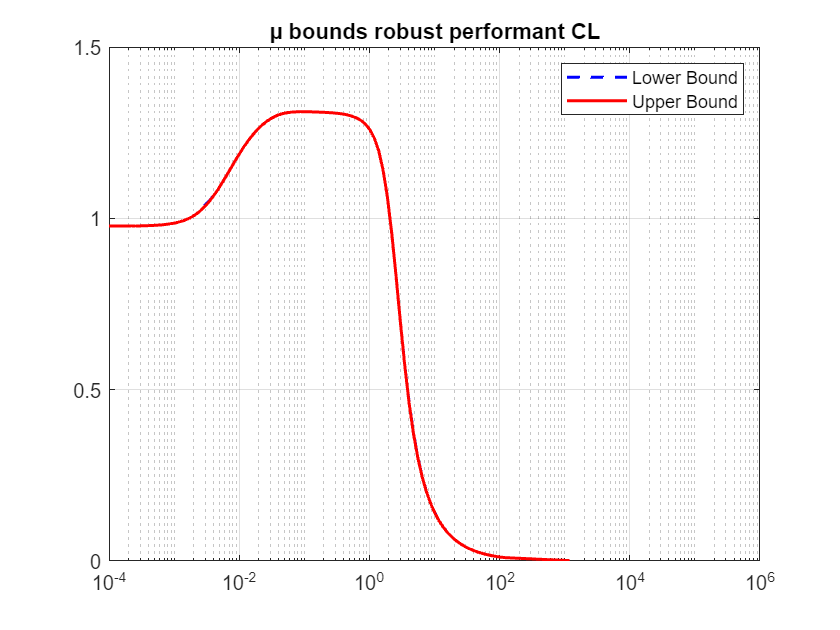

 % extracting the structured singular values for the µ-syn robust controller

p = info4.MussvBnds(1,1);
o = info4.MussvBnds(1,2);
 
 max_nmp_rob = zeros(length(info4.Frequency),1);

 for i=1:length(info4.Frequency)
     max_nmp_rob(i)= p.Response(:,:,i);
 end

 min_nmp_rob = zeros(length(info4.Frequency),1);

 for i=1:length(info4.Frequency)
     min_nmp_rob(i)= o.Response(:,:,i);
 end

figure()

semilogx(info4.Frequency, max_nmp_rob,'b--',info4.Frequency, min_nmp_rob,'r-','LineWidth',1.5);
legend('Lower Bound','Upper Bound');
title('µ bounds robust performant CL');
xlim([1.e-4,1.e+6])
ylim([0,1.5])
grid on;

We can see that µ is  not always <1: in a significantly large neighborood of the critical frequency $\omega^* =0\ldotp 0875\;\textrm{Hz}$ the structured singular value is about 1,27. This result is reasonably the best achieved in terms of robust performance, better  than the $H_{\infty } \;$nominal controller which achieves a robust performance index around 69.66%, and than the PI that achieves about 37,08%, but it is consistently worse than the MP case.

This is another symptom of how much difficult is to control a NMP MIMO system than one will all zeros $\textrm{Re}\left\lbrack \;\right\rbrack <0\ldotp$

Let us compute the step response and try to visualize some possible behaviors (10) of closed loop system under the µ-syn controller.

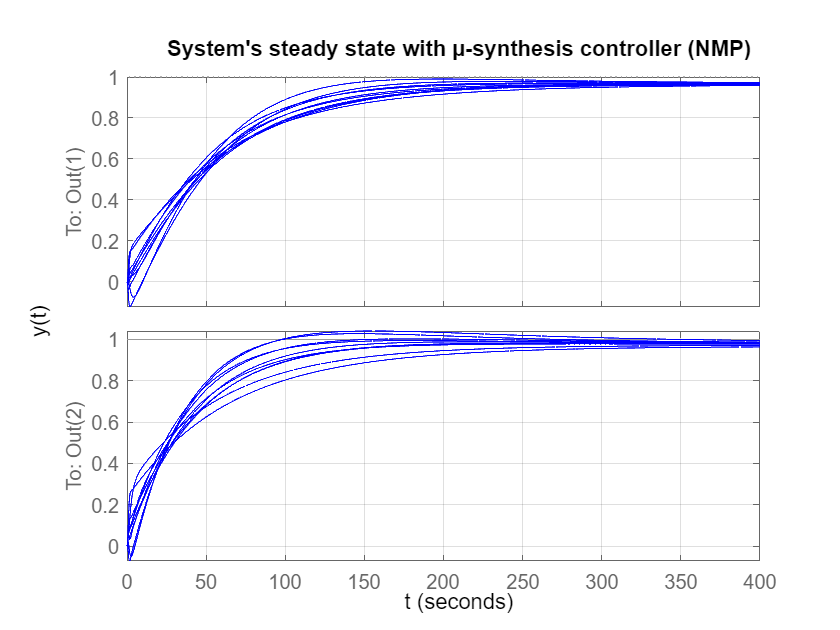

L_NMP_rob = Krob2* PwM2;     % robust open loop
CL_NMP_rob = feedback(L_NMP_rob, eye(2));  % robust closed loop

t1= 0:0.01:400;
r_unit4 = [ones(length(t1),1),ones(length(t1),1)]; 

figure()
samples_NMP = usample(CL_NMP_rob ,10);
lsim(samples_NMP , 'b',r_unit4, t1);
title("System's steady state with µ-synthesis controller (NMP)");
xlabel("t");
ylabel("y(t)");
xlim([0 400]);
grid on;

In the end, we can note two intresting aspects:

- as expected, and resonable, from the plots it is much more evident the uncertainty nature of the closed loop system,  then the MP case, because the system samples tends to assume slightly different behaviors, thanks to the lower robust performance margins; 

- althought this, the system will never diverge under such proposed feedbacks since all of them are proved to be robust stable;

- the closed-loop outputs under the controller designed with the µ-synthesis exhibits a transient faster than the case of PI and the $H_{\infty }$ nominal controller. This is quite surprising since the required bandiwith in the design of the performance weight is the same imposed by the NMP zero's limitation.

This concludes our robustness analysis.

## 5. Decoupling approaches.

Let us try to design two possible decoupler in order to separate the input-output channels $u_1 \to y_1 ,u_2 \to y_2$ minimizing or hopefully nihilating the interactions. We want to find the matrix $D\left(s\right)$ such that the MIMO system behaves like two decoupled SISO systems, with the possibility of controlling them with two additional SISO controllers (Simplified Decoupling approach), or including the control in the design of $D\left(s\right)\;$(Inverted Decoupling approach). In the first case the overall control system will look like:

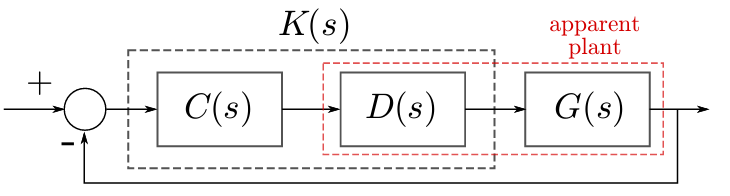

while in the second one $D\left(s\right)\;$will substantially coincide with $K\left(s\right)\ldotp$

### Simplified Decoupling

The first attempt is based on what it is called "Simplified feedforward decoupling". Matrix $D\left(s\right)\;$is composed in this way:

$D\left(s\right)=\left\lbrack \begin{array}{cc}
1 & d_{12} \left(s\right)\\
d_{21} \left(s\right) & 1
\end{array}\right\rbrack$    with $d_{12} \left(s\right)=-\frac{g_{12} \left(s\right)}{g_{11} \left(s\right)}$  and $d_{21} \left(s\right)=-\frac{g_{21} \left(s\right)}{g_{22} \left(s\right)}$.

and the overall "apparent process" will be: 

$G\left(s\right)\;D\left(s\right)=\left\lbrack \begin{array}{cc}
g_{11} \left(s\right)-\frac{{g_{12} \left(s\right)\;g}_{21} \left(s\right)}{g_{22} \left(s\right)} & 0\\
0 & g_{22} \left(s\right)-\frac{{g_{12} \left(s\right)\;g}_{21} \left(s\right)}{g_{11} \left(s\right)}1
\end{array}\right\rbrack$   .  Note that the zeros of $D\left(s\right)$ are the same as $G\left(s\right)$. 

Furthermore, since both  $g_{12} \left(s\right)$ and $g_{21} \left(s\right)$ are non-zero, all transmition zeros not coinciding with poles (i.e. solutions of $\left.\det \left(G\left(s\right)\right)=0\right)$, will appear in the resulting open loop system as zeros of the elements on the diagonal.

This is an important limitation, since we have a case in which the system's transfer function exhibitis a Non Minimum Phase transmition zero.

So we expect two positive zeros, one on each element of the diagonal, that are more difficult to manage since NMP zeros in the SISO case don't have directions and their effects are present in all situations, while in the MIMO case they act only along the zeros directions.

% minimum phase case 

d12mp = - (Gs_mp(1,2)/(Gs_mp(1,1)));  %element out of the diagonal of D(s)
d21mp= - (Gs_mp(2,1)/(Gs_mp(2,2)));   %element out of the diagonal of D(s)
Ds_mp = [1, d12mp; d21mp, 1];

L_mp_app= simplify(zpk(Gs_mp*Ds_mp))     % open loop 

L_mp_app =
 
  From input 1 to output...
       0.041625 (s+0.05802) (s+0.01718) (s+0.01595) (s+0.01107)
   1:  --------------------------------------------------------
          (s+0.04186) (s+0.03334) (s+0.01595)^2 (s+0.01107)
 
       6.1876e-20 s (s+0.07544) (s-0.01294)
   2:  ------------------------------------
           (s+0.03334)^2 (s+0.01107)^3
 
  From input 2 to output...
       -1.585e-19 s (s^2 + 0.001953)
   1:  -----------------------------
        (s+0.04186)^2 (s+0.01595)^3
 
       0.031406 (s+0.05802) (s+0.01718) (s+0.01595) (s+0.01107)
   2:  --------------------------------------------------------
          (s+0.04186) (s+0.03334) (s+0.01595) (s+0.01107)^2
 
Continuous-time zero/pole/gain model.


Since the elements off-diagonal exhibits coefficient of the order of $e^{-19}$, we can consider them identically equal to zero (they are actual different just for numerical issues for MATLAB). So we can consider our decoupling problem solved.

In order to avoid numerical problems in the next few computations, let's substitute zero off-diagonal instead of the remaining very small values, whose presence is a consequence of numerical MATLAB approximations.

L_mp= [L_mp_app(1,1), 0; 0,  L_mp_app(2,2)];  % open looop actually decoupled

zero(L_mp(1,1))

ans =    -0.0580
   -0.0172
   -0.0159
   -0.0111


zero(L_mp(2,2))

ans =    -0.0580
   -0.0172
   -0.0159
   -0.0111


pole(L_mp(1,1))

ans =    -0.0419
   -0.0333
   -0.0159
   -0.0159
   -0.0111


pole(L_mp(2,2))

ans =   -0.0419 + 0.0000i
  -0.0333 + 0.0000i
  -0.0159 + 0.0000i
  -0.0111 + 0.0000i
  -0.0111 - 0.0000i


We can see from the poles and the zeros computation that there are several cancellations in the remaining two SISO elements on the diagonal, but this fact does not constitute a problem since they all are with negative real part. The design of a stabilizing controller can start from here.

Let us explore the Non Minimum Phase Case.

%non minimum phase case
d12nmp = - (Gs_nmp(1,2)/(Gs_nmp(1,1)));
d21nmp= - (Gs_nmp(2,1)/(Gs_nmp(2,2)));
Ds_nmp = zpk([1, d12nmp; d21nmp, 1])

Ds_nmp =
 
  From input 1 to output...
   1:  1
 
        -0.028515 (s+0.01094)
   2:  -----------------------
       (s+0.01782) (s+0.01094)
 
  From input 2 to output...
        -0.041223 (s+0.01582)
   1:  -----------------------
       (s+0.02563) (s+0.01582)
 
   2:  1
 
Continuous-time zero/pole/gain model.
M

L_nmp_app = simplify(zpk(Gs_nmp*Ds_nmp))

L_nmp_app =
 
  From input 1 to output...
       0.024111 (s+0.05623) (s+0.01582) (s+0.01094) (s-0.01278)
   1:  --------------------------------------------------------
          (s+0.01582)^2 (s+0.01782) (s+0.02563) (s+0.01094)
 
       1.4677e-19 (s-0.000503) (s+0.01094) (s+0.02335)
   2:  -----------------------------------------------
                 (s+0.01782)^2 (s+0.01094)^3
 
  From input 2 to output...
       -3.5894e-19 (s+0.01582) (s^2 + 0.0215s + 0.0002711)
   1:  ---------------------------------------------------
                   (s+0.01582)^3 (s+0.02563)^2
 
       0.017478 (s+0.05623) (s+0.01582) (s+0.01094) (s-0.01278)
   2:  --------------------------------------------------------
          (s+0.01782) (s+0.01582) (s+0.02563) (s+0.01094)^2
 
Continuous-time zero/pole/gain model.


Again we have the same numerical problems as before.

L_nmp= [L_nmp_app(1,1), 0; 0,  L_nmp_app(2,2)];  % open looop actually decoupled
zero(L_nmp(1,1))

ans =    -0.0562
    0.0128
   -0.0158
   -0.0109


zero(L_nmp(2,2))

ans =    -0.0562
    0.0128
   -0.0109
   -0.0158


pole(L_nmp)

ans =    -0.0158
   -0.0256
   -0.0158
   -0.0178
   -0.0109
   -0.0178
   -0.0109
   -0.0109
   -0.0256
   -0.0158


We can see the presene of NMP zeros in the two transfer functions, as well as the presence of several cancellations.

### Inverted Decoupling

The goal now is to design a controller able to solve the decoupling problem and at the same time to impose a desired behavior.

So let us choose a possible desired open loop to impose through a positive inner feedback (2x2) decoupler of the form $D\left(s\right)=D_d {\;\left(I-D_d D_o \right)}^{-1} ,$ following the control scheme:

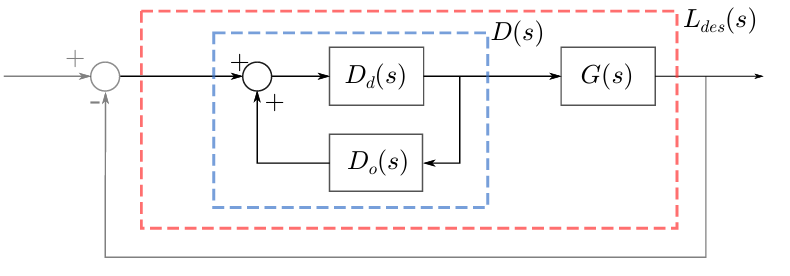

The choices $d_{\textrm{d11}} \left(s\right)=\frac{l_{1\textrm{des}} \left(s\right)}{g_{11} \left(s\right)}$, $d_{\textrm{d22}} \left(s\right)=\frac{l_{2\textrm{des}} \left(s\right)}{g_{22} \left(s\right)}$,  $d_{\textrm{o12}} \left(s\right)=-\frac{g_{12} \left(s\right)}{l_{1\textrm{des}} \left(s\right)}$, $d_{\textrm{o21}} \left(s\right)=-\frac{g_{21} \left(s\right)}{l_{2\textrm{des}} \left(s\right)}$, guarantee that $D\left(s\right)=G^{-1} \left(s\right)\;L_{\textrm{des}} \left(s\right)$, with $L_{\textrm{des}} \left(s\right)$ the desired behavior of the open loop, decoupled and stabilizated.

The resulting control block scheme is:

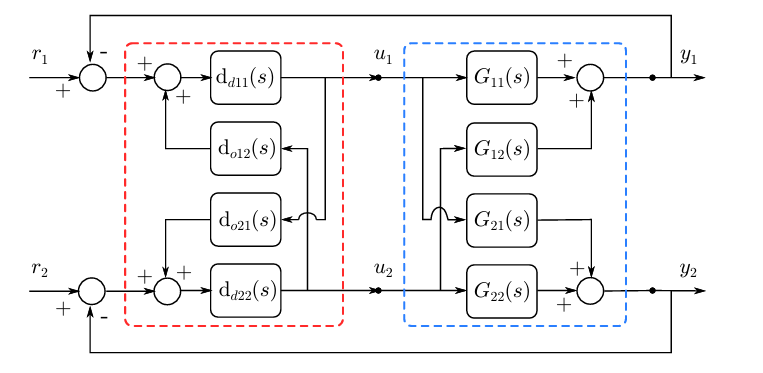

We choose the desired open loop such that it is diagonal, type 1, with all poles $\textrm{Re}\left\lbrack \;\right\rbrack <0,$ i.e. close loop stable and corresponding to two equivalent and indipendent SISO systems.

Its transfer function is: 


$$L_{\textrm{des}} =\frac{100}{s\;\left(s+20\right)}$$


Ldes = [100/(s*(s+20)), 0 ;0 ,100/(s*(s+20))];  % inizializing the desired open loop transfer function

Dd11 = Ldes(1,1)/ Gs_nmp(1,1);
Dd22 = Ldes(2,2)/ Gs_nmp(2,2);

Do12 = - (Gs_nmp(1,2)/(Ldes(1,1)));
Do21 = - (Gs_nmp(2,1)/( Ldes(2,2)));

Dd = [Dd11, 0;0, Dd22];      % building Dd(s)
Do = [0, Do12; Do21, 0];     % building Do(s)

D_ID = Dd*(inv(eye(2)-(Do*Dd)));   % building D(s)
L_ID_app = Gs_nmp * D_ID            % computing G(s) D(s)

L_ID_app =
 
  From input 1 to output...
                 3.794e07 s^17 + 3.802e09 s^16 + 1.525e11 s^15 + 3.065e12 s^14 + 3.096e13 s^13 + 1.275e14 s^12 + 2.447e13 s^11 + 1.871e12 s^10 + 6.972e10 s^9 + 1.16e09 s^8 - 1.528e06 s^7 - 3.709e05 s^6 - 5055 s^5 - 4.737 s^4 + 0.4714 s^3 + 0.004267 s^2 + 1.206e-05 s
   1:  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
       3.794e05 s^19 + 4.561e07 s^18 + 2.286e09 s^17 + 6.116e10 s^16 + 9.227e11 s^15 + 7.466e12 s^14 + 2.574e13 s^13 + 4.913e12 s^12 + 3.75e11 s^11 + 1.396e10 s^10 + 2.32e08 s^9 - 3.094e05 s^8 - 7.423e04 s^7 - 1011 s^6 - 0.9426 s^5 + 0.09432 s^4 + 0.0008536 s^3 + 2.411e-06 s^2
 
                1.546e-06 s^16 + 0.0001238 s^15 + 0.003719 s^14 + 0.04965 s^13 + 0.2498 s^12 + 0.008789 s^11 - 0.003662 s^10 - 0.00044

Since we have the usual numerical problems, we substitute zero at the off-diagonal positions.

Let us now compare the resulting open loop with the desired one from a frequency domain point of view. 

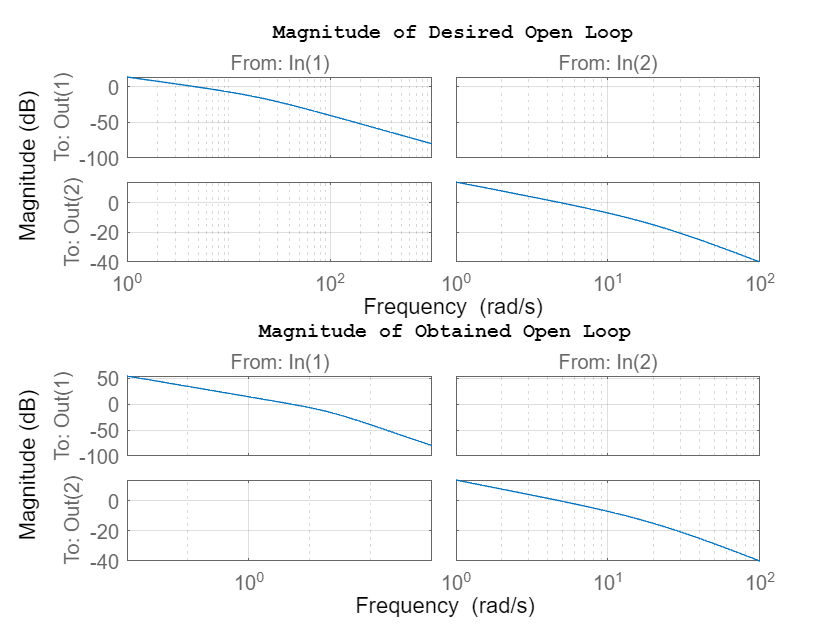

L_ID= [L_ID_app(1,1), 0;0, L_ID_app(2,2)];   % resultingo L(s) with 0 off-diagonal

figure

subplot(211)

bodemag(Ldes); grid on
Tit = title('Magnitude of Desired Open Loop');
set(Tit,'fontName','Courier','FontSize',10);
xlim([1E-0,1E+2]);

subplot(212)

bodemag(L_ID);grid on
Tit = title('Magnitude of Obtained Open Loop');
set(Tit,'fontName','Courier','FontSize',10);
xlim([1E-0,1E+2]);

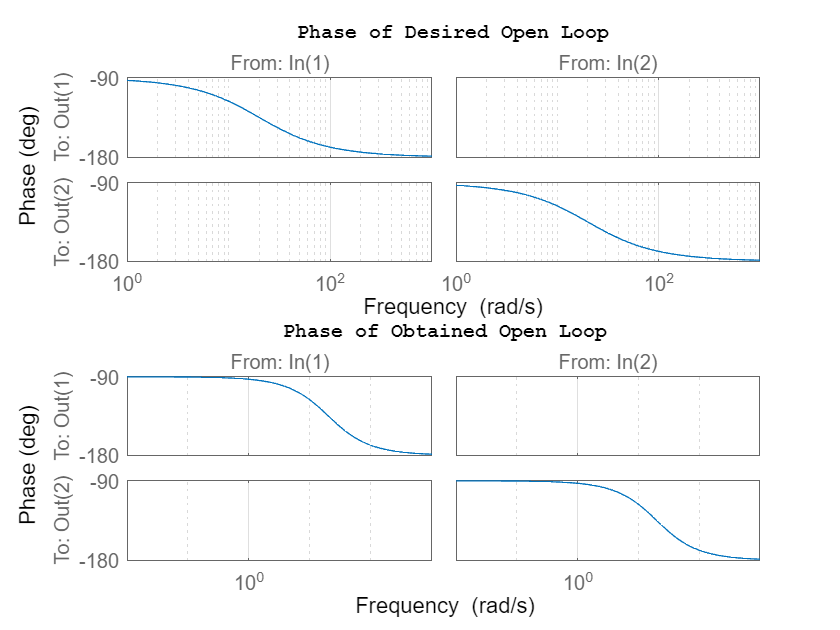

figure

subplot(211)

phdes = bodeplot(Ldes); grid on
setoptions(phdes,'MagVisible', 'off');
Tit = title('Phase of Desired Open Loop');
set(Tit,'fontName','Courier','FontSize',10);

subplot(212)

phobt = bodeplot(L_ID); grid on
setoptions(phobt,'MagVisible', 'off');
Tit = title('Phase of Obtained Open Loop');
set(Tit,'fontName','Courier','FontSize',10);

First thing we note is that while the two SISO model on the diagonal of the obtained open loop exhibits the same phase, they differ a bit from the point of view of the magnitude, signal that we are made little numerical errors in computations. 

The form of the phases and of the magnitudes are more or less the same as the ones of the desired open loops, but they result a bit anticipated in frequency, exept for the magnitude of the second element on the diagonal, that it exactly the same as the desired one.

Let us evaluate the performances in terms of stability and reference reproduction's capabilities.

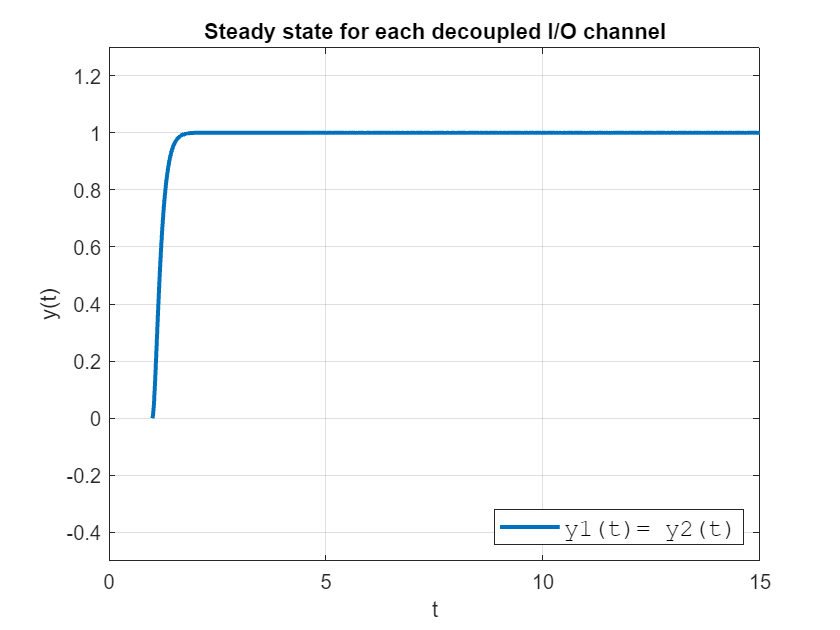

T_ID = L_ID(1,1)/(1+L_ID(1,1));   % complementary sensitivity
r_unit3 = [ones(length(t),1)];    % dummy step reference to check if the controller works

figure()

ycl3 = lsim(T_ID, r_unit3, t);
plot(t, ycl3, 'LineWidth', 2), grid on;
title("Steady state for each decoupled I/O channel");
xlabel("t");
ylabel("y(t)");
legend('y1(t)= y2(t)','FontName','courier','FontSize',12,'Location','SouthEast')
xlim([0 15]);
ylim([-0.5 1.3])

So as expected the inverted decoupler is able to make the closed loop system decoupled and exhibiting a behavior close to the desired, although the overall open loop is not excactly the same as the desired one.

We expect an high control effort peak due to the fact that we are decoupling and stabilizing at the same time.

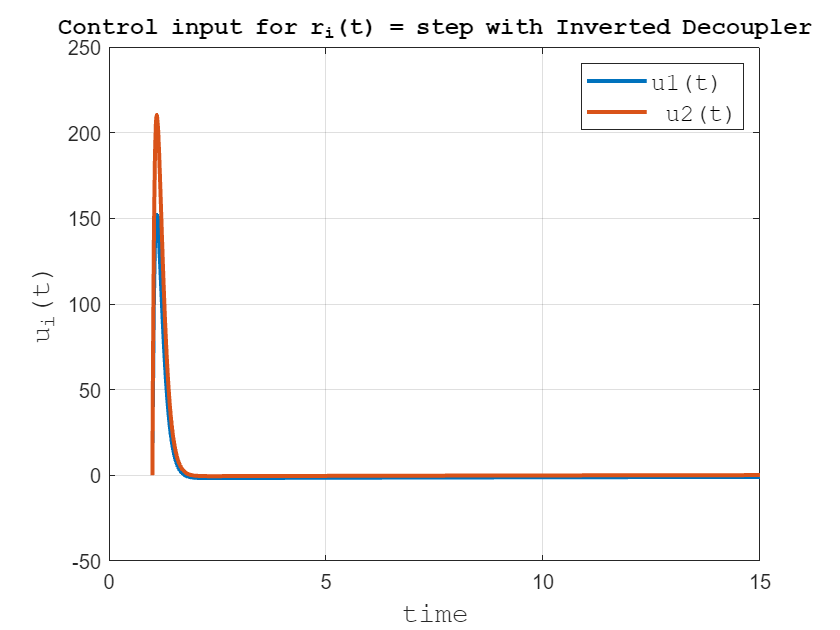

Cso = D_ID/(eye(2)+ L_ID_app);  % control sensitivity function

m0 =  lsim(Cso, r_unit2, t);
plot(t,m0,'LineWidth',2); grid
title('Control input for r_{i}(t) = step with Inverted Decoupler','FontName','courier','FontSize',12)
xlabel('time','FontName','courier','FontSize',14);
xlim([0 15]);
ylabel('u_{i}(t)','FontName','courier','FontSize',14);
legend('u1(t)',' u2(t)','FontName','courier','FontSize',12,'Location','NorthEast')